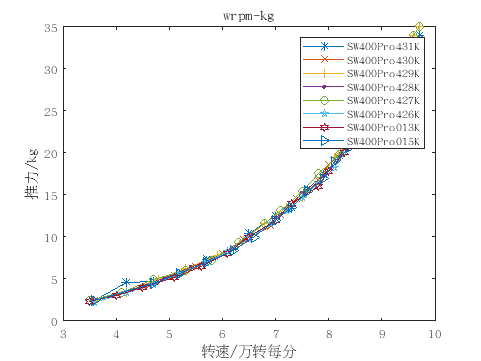

plot(SW400Pro431K.wrpm,SW400Pro431K.kg,'*-');
hold on;
plot(SW400Pro430K.wrpm,SW400Pro430K.kg,'x-');
plot(SW400Pro429K.wrpm,SW400Pro429K.kg,'+-');
plot(SW400Pro428K.wrpm,SW400Pro428K.kg,'.-');
plot(SW400Pro427K.wrpm,SW400Pro427K.kg,'o-');
plot(SW400Pro426K.wrpm,SW400Pro426K.kg,'p-');
plot(SW400Pro013K.wrpm,SW400Pro013K.kg,'h-');
plot(SW400Pro015K.wrpm,SW400Pro015K.kg,'>-');
hold off;
legend('SW400Pro431K', ...
       'SW400Pro430K', ...
       'SW400Pro429K', ...
       'SW400Pro428K', ...
       'SW400Pro427K', ...
       'SW400Pro426K', ...
       'SW400Pro013K', ...
       'SW400Pro015K')
title('wrpm-kg');
xlabel('转速/万转每分');
ylabel('推力/kg');

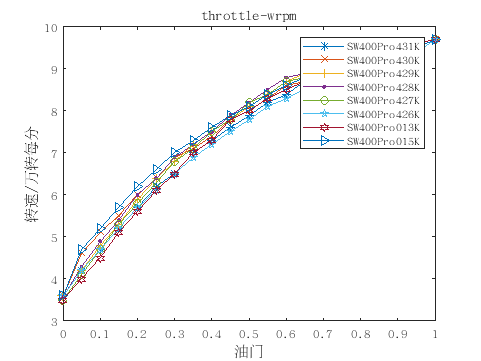

figure;
plot(SW400Pro431K.throttle,SW400Pro431K.wrpm,'*-');
hold on;
plot(SW400Pro430K.throttle,SW400Pro430K.wrpm,'x-');
plot(SW400Pro429K.throttle,SW400Pro429K.wrpm,'+-');
plot(SW400Pro428K.throttle,SW400Pro428K.wrpm,'.-');
plot(SW400Pro427K.throttle,SW400Pro427K.wrpm,'o-');
plot(SW400Pro426K.throttle,SW400Pro426K.wrpm,'p-');
plot(SW400Pro013K.throttle,SW400Pro013K.wrpm,'h-');
plot(SW400Pro015K.throttle,SW400Pro015K.wrpm,'>-');
hold off;
legend('SW400Pro431K', ...
       'SW400Pro430K', ...
       'SW400Pro429K', ...
       'SW400Pro428K', ...
       'SW400Pro427K', ...
       'SW400Pro426K', ...
       'SW400Pro013K', ...
       'SW400Pro015K')
title('throttle-wrpm');
ylabel('转速/万转每分');
xlabel('油门');

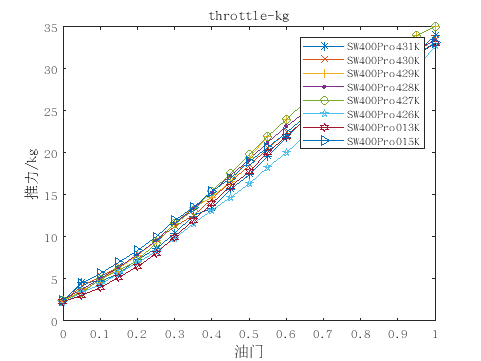

figure;
plot(SW400Pro431K.throttle,SW400Pro431K.kg,'*-');
hold on;
plot(SW400Pro430K.throttle,SW400Pro430K.kg,'x-');
plot(SW400Pro429K.throttle,SW400Pro429K.kg,'+-');
plot(SW400Pro428K.throttle,SW400Pro428K.kg,'.-');
plot(SW400Pro427K.throttle,SW400Pro427K.kg,'o-');
plot(SW400Pro426K.throttle,SW400Pro426K.kg,'p-');
plot(SW400Pro013K.throttle,SW400Pro013K.kg,'h-');
plot(SW400Pro015K.throttle,SW400Pro015K.kg,'>-');
hold off;
legend('SW400Pro431K', ...
       'SW400Pro430K', ...
       'SW400Pro429K', ...
       'SW400Pro428K', ...
       'SW400Pro427K', ...
       'SW400Pro426K', ...
       'SW400Pro013K', ...
       'SW400Pro015K')
title('throttle-kg');
ylabel('推力/kg');
xlabel('油门');

## throttle-rpm 拟合

% plot(SW400Pro431K.throttle,SW400Pro431K.wrpm);
% plot(SW400Pro430K.throttle,SW400Pro430K.wrpm);
% plot(SW400Pro429K.throttle,SW400Pro429K.wrpm);
% plot(SW400Pro428K.throttle,SW400Pro428K.wrpm);
% plot(SW400Pro427K.throttle,SW400Pro427K.wrpm);
% plot(SW400Pro426K.throttle,SW400Pro426K.wrpm);
% plot(SW400Pro013K.throttle,SW400Pro013K.wrpm);
% plot(SW400Pro015K.throttle,SW400Pro015K.wrpm);

% Throttle_431k = SW400Pro431K.throttle;
% Wrpm_431k = SW400Pro431K.wrpm;
Throttle_426k = SW400Pro426K.throttle;
Wrpm_426k = SW400Pro426K.wrpm;

throttle_total = [SW400Pro431K.throttle;
SW400Pro430K.throttle;
SW400Pro429K.throttle;
SW400Pro428K.throttle;
SW400Pro427K.throttle;
SW400Pro426K.throttle;
SW400Pro013K.throttle;
SW400Pro015K.throttle];

wrpm_total = [SW400Pro431K.wrpm;
SW400Pro430K.wrpm;
SW400Pro429K.wrpm;
SW400Pro428K.wrpm;
SW400Pro427K.wrpm;
SW400Pro426K.wrpm;
SW400Pro013K.wrpm;
SW400Pro015K.wrpm];

fitParam431_thro_wrpm = [1.564	-7.553	12.03	3.592];
fitParam430_thro_wrpm = [3.768	-10.95	13.07	3.792];
fitParam429_thro_wrpm = [2.322	-9.578	13.36	3.571];
fitParam428_thro_wrpm = [2.731	-10.35	13.68	3.609];
fitParam427_thro_wrpm = [2.689	-10.29	13.82	3.453];
fitParam426_thro_wrpm = [2.748	-8.904	12.18	3.589];
fitParam015_thro_wrpm = [5.688	-14.2	14.39	3.816];
fitParam013_thro_wrpm = [1.114	-7.434	12.58	3.406];
total_thro_wrpm = [2.828	-9.909	13.14	3.603];

fitParam431_wrpm_thro = [0.005096	-0.08134	0.5238	-1.083];
fitParam430_wrpm_thro = [0.004525	-0.06629	0.4054	-0.8278];
fitParam429_wrpm_thro = [0.006454	-0.107	0.6682	-1.337];
fitParam428_wrpm_thro = [0.00683	-0.1134	0.7007	-1.391];
fitParam427_wrpm_thro = [0.006381	-0.1047	0.6472	-1.273];
fitParam426_wrpm_thro = [0.003779	-0.05437	0.3554	-0.7572];
fitParam015_wrpm_thro = [0.004854	-0.06976	0.4056	-0.7949];
fitParam013_wrpm_thro = [0.005742	-0.09452	0.601	-1.204];
total_wrpm_thro = [0.005221	-0.08185	0.5102	-1.028];

throttle_428 = SW400Pro428K.throttle;
wrpm_013 = SW400Pro013K.wrpm;



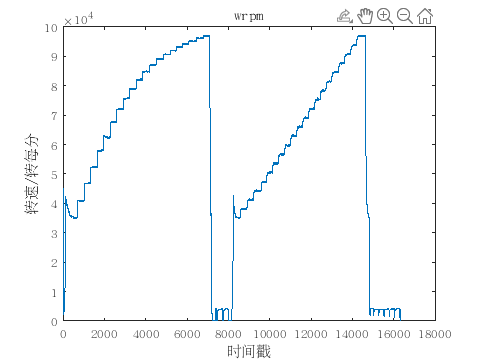

w_raw = SW400ProK013.engine_rpm;
throttle_raw = SW400ProK013.rc_input1;
fit_raw = fitParam430_wrpm_thro;
range = 1:length(w_raw);
% range = 5700:15956;
% range = 5700:9600;

figure;
plot(w_raw(range));
title('wrpm');
ylabel('转速/转每分');
xlabel('时间戳');

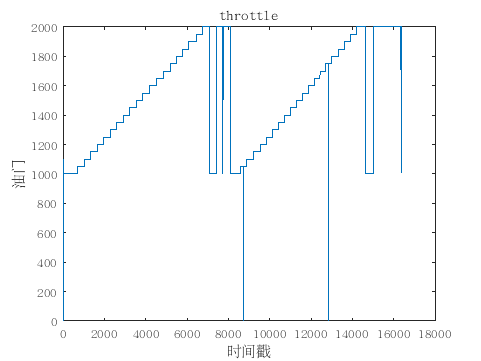


figure;
plot(throttle_raw(range));
title('throttle');
ylabel('油门');
xlabel('时间戳');

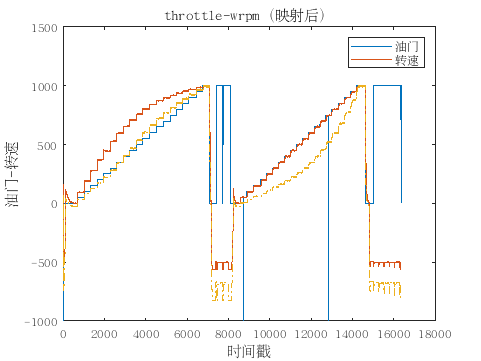


maxRPM = 97000;
minRPM = 35000;
minThrottle = 1000;
maxThrottle = 2000;

w_p = (w_raw - minRPM)/(maxRPM-minRPM)*minThrottle;
t_p = throttle_raw - minThrottle;
wt_p = polyval(fit_raw ,w_raw.*1e-4).*1000;
% tt_p = (polyval(fitParam426_thro_wrpm,t_p/1000.0) - minRPM*1e-4)/(maxRPM-minRPM)*1e4*minThrottle;

figure;
plot(t_p(range));
hold on;
plot(w_p(range));
plot(wt_p(range),'-.');
hold off;
legend('油门', ...
       '转速');
title('throttle-wrpm（映射后）');
ylabel('油门-转速');
xlabel('时间戳');

## controller design

s = tf('s');
G = 1/(s+1)/(0.08*s+1);

K1 = 0.1668;
FF = 1/(0.15*s + 1);
a = 19.05;
C1 = K1*(s+a)/s;
C2 = 1;
% C3 = K1*c_n/(s + c_n);

Tyd = G/(1 + C1*G);
Tyr = (C1 + C2)*G/(1 + C1*G);

Tyd_ramp = Tyd/s;
Tyr_ramp = Tyr/s;
R_ramp = 1/s;

Tyd_acc = Tyd/s^2;
Tyr_acc = Tyr/s^2;
R_acc = 1/s^2;

%% controller setup
Ts = 0.01;%100ms interval

%smith predictor
Tsp = 0.25;
Tsp_delay = 0.13;

% continue pid gain
% c_d = 0.15;
% 
% c_p = 12*c_d;
% c_i = 17*c_d;
% 
% c_d = 0.3;

%pid parameter
k = 1;
c_d = 0.01*k;

c_p = 1.8*k;
c_i = 3.5*k;

c_n = 10;

Ti = c_p/c_i;
Td = c_d/c_p;
Tt = sqrt(Ti*Td);

% Td = 0;
Tg = 0.1;

c_upbound = 300;
c_downbound = -300;

% T0 = 0.15;
% T1 = 0.09;
% Ti = 0.22; %%名义模型的时间常数
% kc = Ti/T0;
% 
% c_p = kc;
% Td = 0;


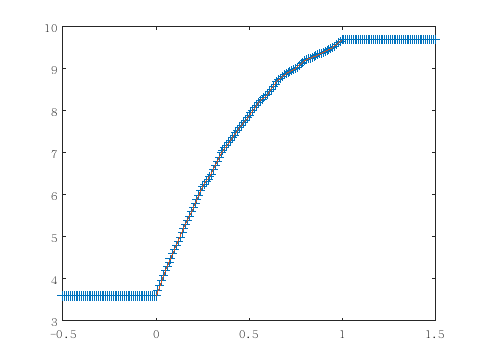

test_input = -0.5:0.01:1.5;
test_output = [3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.600000,3.720000,3.840000,3.960000,4.080000,4.200000,4.301000,4.401000,4.500000,4.600000,4.700000,4.800000,4.900000,5.000000,5.100000,5.200000,5.300000,5.400000,5.500000,5.600000,5.700000,5.800000,5.900000,6.000000,6.100000,6.200000,6.260000,6.320000,6.380000,6.440000,6.500000,6.600000,6.700000,6.800000,6.900000,7.000000,7.060000,7.120000,7.180000,7.240000,7.300000,7.360000,7.420000,7.480000,7.540000,7.600000,7.660000,7.720000,7.780000,7.840000,7.900000,7.960000,8.020000,8.080000,8.140000,8.200000,8.240000,8.280000,8.320000,8.360000,8.400000,8.460000,8.520000,8.580000,8.639999,8.700000,8.740000,8.780000,8.820000,8.860000,8.900000,8.920000,8.940000,8.960000,8.980000,9.000000,9.040000,9.080000,9.120000,9.160000,9.200000,9.220000,9.240000,9.260000,9.280000,9.300000,9.320000,9.340000,9.360000,9.380000,9.400000,9.420000,9.440000,9.460000,9.480000,9.500000,9.540000,9.580000,9.620000,9.660000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000,9.700000];

figure;
plot(test_input,test_output,'+');
hold on;
plot(SW400Pro431K.throttle,SW400Pro431K.wrpm);
hold off;

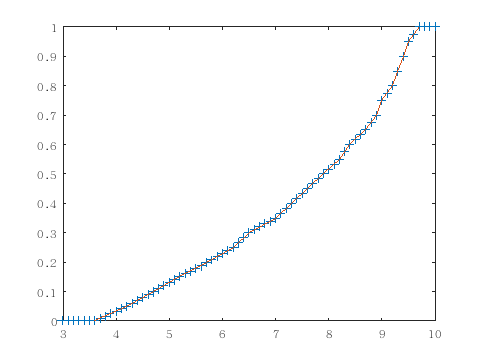


test_input = 3.0:0.1:10.0;
test_output = [0.000000,0.000000,0.000000,0.000000,0.000000,0.000000,0.000000,0.008333,0.016667,0.025000,0.033333,0.041667,0.050000,0.060000,0.070000,0.080000,0.090000,0.100000,0.110000,0.120000,0.130000,0.140000,0.150000,0.160000,0.170000,0.180000,0.190000,0.200000,0.210000,0.220000,0.230000,0.240000,0.250000,0.266667,0.283333,0.300000,0.310000,0.320000,0.330000,0.340000,0.350000,0.366667,0.383333,0.400000,0.416667,0.433333,0.450000,0.466667,0.483333,0.500000,0.516667,0.533333,0.550000,0.575000,0.600000,0.616667,0.633333,0.650000,0.675000,0.700000,0.750000,0.775000,0.800000,0.850000,0.900000,0.950000,0.975000,1.000000,1.000000,1.000000,1.000000];
figure;
plot(test_input,test_output,'+');
hold on;
plot(SW400Pro431K.wrpm,SW400Pro431K.throttle);
hold off;

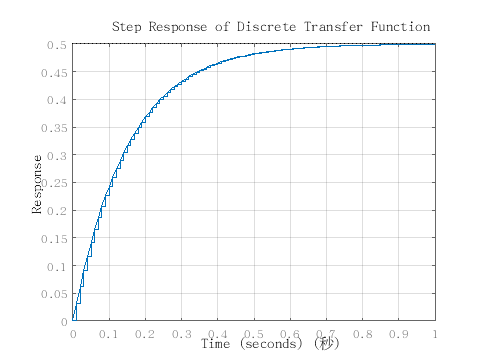

t = 0:199;
t = t*0.01;
tf_test_output = [0.000000 ,0.032258 ,0.062435 ,0.090665 ,0.117074 ,0.141779 ,0.164890 ,0.186510 ,0.206735 ,0.225655 ,0.243355 ,0.259913 ,0.275402 ,0.289892 ,0.303448 ,0.316129 ,0.327991 ,0.339089 ,0.349470 ,0.359182 ,0.368267 ,0.376766 ,0.384716 ,0.392154 ,0.399112 ,0.405621 ,0.411710 ,0.417406 ,0.422735 ,0.427719 ,0.432383 ,0.436745 ,0.440826 ,0.444644 ,0.448215 ,0.451556 ,0.454682 ,0.457605 ,0.460341 ,0.462899 ,0.465293 ,0.467532 ,0.469627 ,0.471586 ,0.473420 ,0.475135 ,0.476739 ,0.478240 ,0.479643 ,0.480957 ,0.482185 ,0.483335 ,0.484410 ,0.485416 ,0.486357 ,0.487237 ,0.488060 ,0.488831 ,0.489551 ,0.490226 ,0.490856 ,0.491446 ,0.491998 ,0.492514 ,0.492997 ,0.493449 ,0.493872 ,0.494267 ,0.494637 ,0.494983 ,0.495307 ,0.495610 ,0.495893 ,0.496158 ,0.496406 ,0.496638 ,0.496855 ,0.497058 ,0.497247 ,0.497425 ,0.497591 ,0.497747 ,0.497892 ,0.498028 ,0.498155 ,0.498274 ,0.498386 ,0.498490 ,0.498587 ,0.498679 ,0.498764 ,0.498844 ,0.498918 ,0.498988 ,0.499053 ,0.499115 ,0.499172 ,0.499225 ,0.499275 ,0.499322 ,0.499366 ,0.499407 ,0.499445 ,0.499481 ,0.499514 ,0.499546 ,0.499575 ,0.499602 ,0.499628 ,0.499652 ,0.499675 ,0.499696 ,0.499715 ,0.499734 ,0.499751 ,0.499767 ,0.499782 ,0.499796 ,0.499809 ,0.499822 ,0.499833 ,0.499844 ,0.499854 ,0.499864 ,0.499872 ,0.499881 ,0.499888 ,0.499896 ,0.499902 ,0.499909 ,0.499915 ,0.499920 ,0.499925 ,0.499930 ,0.499935 ,0.499939 ,0.499943 ,0.499947 ,0.499950 ,0.499953 ,0.499956 ,0.499959 ,0.499962 ,0.499964 ,0.499967 ,0.499969 ,0.499971 ,0.499973 ,0.499975 ,0.499976 ,0.499978 ,0.499979 ,0.499981 ,0.499982 ,0.499983 ,0.499984 ,0.499985 ,0.499986 ,0.499987 ,0.499988 ,0.499989 ,0.499990 ,0.499990 ,0.499991 ,0.499992 ,0.499992 ,0.499993 ,0.499993 ,0.499994 ,0.499994 ,0.499995 ,0.499995 ,0.499995 ,0.499996 ,0.499996 ,0.499996 ,0.499996 ,0.499997 ,0.499997 ,0.499997 ,0.499997 ,0.499998 ,0.499998 ,0.499998 ,0.499998 ,0.499998 ,0.499998 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.499999 ,0.500000 ,0.500000];

sys = tf([Ts],[Ts+0.3 Ts-0.3],Ts);

% 生成阶跃响应曲线
figure; % 新建一个图形窗口
step(sys);
title('Step Response of Discrete Transfer Function');
xlabel('Time (seconds)');
ylabel('Response');
grid on; % 显示网格
hold on;

plot(t(1:99),tf_test_output(1:99));
hold off;

## controller test

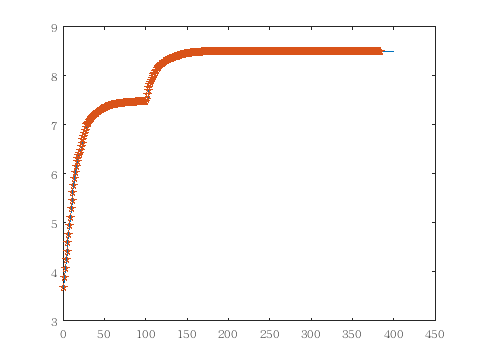

t = 0:0.01:2;
tt = 0:0.01:4;
throttle_output = [0.313978, 0.341034, 0.366343, 0.390020, 0.412169, 0.432890, 0.452273, 0.458280, 0.439169, 0.434311, 0.437754, 0.437420, 0.434376, 0.432368, 0.431308, 0.430057, 0.428572, 0.427199, 0.425974, 0.424796, 0.423645, 0.422554, 0.421528, 0.420557, 0.419636, 0.418769, 0.417955, 0.417190, 0.416473, 0.415805, 0.415180, 0.414599, 0.414060, 0.413563, 0.413102, 0.412679, 0.412291, 0.411936, 0.411614, 0.411322, 0.411059, 0.410823, 0.410613, 0.410428, 0.410267, 0.410128, 0.410008, 0.409910, 0.409830, 0.409768, 0.409721, 0.409690, 0.409676, 0.409673, 0.409683, 0.409706, 0.409740, 0.409785, 0.409839, 0.409904, 0.409975, 0.410055, 0.410143, 0.410238, 0.410338, 0.410447, 0.410558, 0.410676, 0.410798, 0.410924, 0.411054, 0.411189, 0.411326, 0.411466, 0.411610, 0.411754, 0.411901, 0.412052, 0.412203, 0.412355, 0.412509, 0.412665, 0.412821, 0.412978, 0.413137, 0.413295, 0.413454, 0.413613, 0.413772, 0.413932, 0.414091, 0.414250, 0.414411, 0.414569, 0.414727, 0.414886, 0.415044, 0.415201, 0.415358, 0.415514, 0.415669, 0.738750, 0.750228, 0.760966, 0.579260, 0.557507, 0.611914, 0.622034, 0.606150, 0.602047, 0.606527, 0.607909, 0.606448, 0.605721, 0.605879, 0.605852, 0.605529, 0.605238, 0.605030, 0.604821, 0.604587, 0.604358, 0.604139, 0.603931, 0.603727, 0.603533, 0.603351, 0.603177, 0.603013, 0.602859, 0.602718, 0.602587, 0.602467, 0.602358, 0.602259, 0.602173, 0.602094, 0.602023, 0.601970, 0.601919, 0.601878, 0.601848, 0.601823, 0.601810, 0.601805, 0.601804, 0.601809, 0.601824, 0.601845, 0.601867, 0.601903, 0.601941, 0.601979, 0.602028, 0.602078, 0.602134, 0.602193, 0.602259, 0.602322, 0.602393, 0.602466, 0.602541, 0.602617, 0.602700, 0.602783, 0.602865, 0.602953, 0.603039, 0.603131, 0.603221, 0.603313, 0.603408, 0.603500, 0.603595, 0.603693, 0.603789, 0.603888, 0.603984, 0.604079, 0.604181, 0.604281, 0.604377, 0.604477, 0.604577, 0.604677, 0.604775, 0.604872, 0.604972, 0.605070, 0.605170, 0.605266, 0.605366, 0.605462, 0.605559, 0.605657, 0.605750, 0.605849, 0.605942, 0.606037, 0.606132, 0.606226];
pid_lastoutput = [5.662627, 2.451715, 1.144694, 0.671902, 0.483459, 0.391509, 0.333300, 0.287874, 0.251800, 0.231074, 0.219672, 0.205450, 0.189415, 0.175254, 0.162825, 0.150938, 0.139504, 0.128824, 0.118892, 0.109568, 0.100798, 0.092579, 0.084884, 0.077675, 0.070918, 0.064593, 0.058672, 0.053129, 0.047943, 0.043094, 0.038558, 0.034318, 0.030357, 0.026657, 0.023201, 0.019976, 0.016966, 0.014159, 0.011543, 0.009106, 0.006835, 0.004720, 0.002754, 0.000925, -0.000773, -0.002351, -0.003816, -0.005173, -0.006430, -0.007594, -0.008671, -0.009666, -0.010582, -0.011429, -0.012208, -0.012923, -0.013579, -0.014181, -0.014731, -0.015232, -0.015689, -0.016104, -0.016479, -0.016817, -0.017122, -0.017392, -0.017636, -0.017849, -0.018038, -0.018201, -0.018344, -0.018462, -0.018563, -0.018645, -0.018709, -0.018760, -0.018794, -0.018814, -0.018822, -0.018819, -0.018804, -0.018778, -0.018745, -0.018701, -0.018649, -0.018591, -0.018526, -0.018454, -0.018376, -0.018293, -0.018205, -0.018113, -0.018015, -0.017916, -0.017812, -0.017705, -0.017595, -0.017483, -0.017367, -0.017250, -0.017132, 2.378715, 0.964039, 0.334774, 0.108248, 0.077098, 0.122714, 0.124611, 0.101034, 0.089734, 0.087481, 0.082565, 0.075212, 0.068973, 0.063975, 0.059125, 0.054289, 0.049777, 0.045621, 0.041718, 0.038028, 0.034566, 0.031323, 0.028286, 0.025435, 0.022765, 0.020267, 0.017926, 0.015735, 0.013685, 0.011771, 0.009980, 0.008308, 0.006747, 0.005290, 0.003933, 0.002665, 0.001481, 0.000388, -0.000636, -0.001588, -0.002469, -0.003291, -0.004050, -0.004752, -0.005405, -0.006011, -0.006566, -0.007079, -0.007556, -0.007988, -0.008388, -0.008759, -0.009092, -0.009400, -0.009678, -0.009933, -0.010160, -0.010371, -0.010557, -0.010723, -0.010873, -0.011007, -0.011120, -0.011221, -0.011310, -0.011383, -0.011448, -0.011496, -0.011538, -0.011569, -0.011590, -0.011605, -0.011611, -0.011607, -0.011599, -0.011583, -0.011564, -0.011542, -0.011507, -0.011470, -0.011434, -0.011389, -0.011340, -0.011289, -0.011236, -0.011181, -0.011121, -0.011060, -0.010995, -0.010931, -0.010861, -0.010794, -0.010724, -0.010651, -0.010580, -0.010503, -0.010430, -0.010355, -0.010277, -0.010200];
pid_p_out = [1.149200, 1.128891, 1.087514, 1.044767, 1.000938, 0.956282, 0.911032, 0.865395, 0.820342, 0.778334, 0.739926, 0.703483, 0.668616, 0.635669, 0.604656, 0.575354, 0.547630, 0.521437, 0.496706, 0.473349, 0.451287, 0.430452, 0.410778, 0.392201, 0.374659, 0.358095, 0.342455, 0.327687, 0.313741, 0.300571, 0.288134, 0.276386, 0.265290, 0.254807, 0.244903, 0.235544, 0.226699, 0.218337, 0.210432, 0.202956, 0.195884, 0.189193, 0.182861, 0.176866, 0.171190, 0.165813, 0.160717, 0.155887, 0.151307, 0.146961, 0.142837, 0.138920, 0.135201, 0.131665, 0.128303, 0.125104, 0.122060, 0.119160, 0.116396, 0.113761, 0.111247, 0.108847, 0.106554, 0.104361, 0.102264, 0.100257, 0.098334, 0.096491, 0.094723, 0.093025, 0.091394, 0.089827, 0.088318, 0.086866, 0.085467, 0.084117, 0.082815, 0.081557, 0.080342, 0.079166, 0.078028, 0.076925, 0.075856, 0.074820, 0.073814, 0.072836, 0.071885, 0.070961, 0.070061, 0.069184, 0.068329, 0.067495, 0.066682, 0.065887, 0.065111, 0.064352, 0.063610, 0.062883, 0.062171, 0.061474, 0.060791, 0.546320, 0.524775, 0.482640, 0.441124, 0.412691, 0.398806, 0.383486, 0.364740, 0.347281, 0.331966, 0.317374, 0.303115, 0.289556, 0.276800, 0.264704, 0.253188, 0.242258, 0.231900, 0.222079, 0.212765, 0.203934, 0.195563, 0.187630, 0.180112, 0.172986, 0.166235, 0.159837, 0.153774, 0.148028, 0.142583, 0.137423, 0.132533, 0.127897, 0.123502, 0.119335, 0.115383, 0.111634, 0.108079, 0.104704, 0.101501, 0.098460, 0.095572, 0.092829, 0.090222, 0.087743, 0.085385, 0.083143, 0.081008, 0.078975, 0.077039, 0.075193, 0.073432, 0.071753, 0.070149, 0.068618, 0.067154, 0.065755, 0.064415, 0.063133, 0.061904, 0.060726, 0.059596, 0.058511, 0.057469, 0.056467, 0.055503, 0.054575, 0.053682, 0.052820, 0.051989, 0.051186, 0.050410, 0.049661, 0.048935, 0.048233, 0.047552, 0.046892, 0.046251, 0.045630, 0.045026, 0.044438, 0.043866, 0.043310, 0.042768, 0.042239, 0.041723, 0.041220, 0.040728, 0.040248, 0.039778, 0.039319, 0.038869, 0.038429, 0.037998, 0.037575, 0.037160, 0.036753, 0.036353, 0.035961, 0.035576];
pid_i_out = [0.006760, -0.099755, -0.254748, -0.309209, -0.324380, -0.325286, -0.320450, -0.312792, -0.303620, -0.294216, -0.285285, -0.276795, -0.268724, -0.261051, -0.253755, -0.246814, -0.240208, -0.233920, -0.227931, -0.222224, -0.216785, -0.211599, -0.206650, -0.201927, -0.197416, -0.193106, -0.188985, -0.185043, -0.181270, -0.177656, -0.174193, -0.170872, -0.167686, -0.164627, -0.161687, -0.158861, -0.156142, -0.153524, -0.151002, -0.148570, -0.146224, -0.143959, -0.141770, -0.139654, -0.137607, -0.135625, -0.133704, -0.131841, -0.130034, -0.128280, -0.126575, -0.124918, -0.123305, -0.121736, -0.120206, -0.118716, -0.117262, -0.115843, -0.114457, -0.113103, -0.111780, -0.110485, -0.109218, -0.107977, -0.106762, -0.105571, -0.104402, -0.103256, -0.102132, -0.101027, -0.099942, -0.098876, -0.097828, -0.096798, -0.095784, -0.094787, -0.093805, -0.092838, -0.091886, -0.090947, -0.090023, -0.089111, -0.088212, -0.087326, -0.086452, -0.085589, -0.084738, -0.083898, -0.083068, -0.082249, -0.081440, -0.080641, -0.079852, -0.079072, -0.078301, -0.077540, -0.076787, -0.076043, -0.075307, -0.074580, -0.073861, -0.070290, -0.110472, -0.165878, -0.176070, -0.171825, -0.167052, -0.162450, -0.158049, -0.153860, -0.149865, -0.146045, -0.142395, -0.138909, -0.135577, -0.132392, -0.129346, -0.126431, -0.123642, -0.120972, -0.118414, -0.115963, -0.113613, -0.111359, -0.109195, -0.107118, -0.105123, -0.103205, -0.101360, -0.099585, -0.097875, -0.096228, -0.094640, -0.093108, -0.091630, -0.090201, -0.088820, -0.087485, -0.086193, -0.084941, -0.083728, -0.082552, -0.081410, -0.080302, -0.079225, -0.078178, -0.077160, -0.076169, -0.075203, -0.074262, -0.073344, -0.072449, -0.071575, -0.070721, -0.069886, -0.069070, -0.068271, -0.067489, -0.066723, -0.065973, -0.065238, -0.064516, -0.063808, -0.063114, -0.062431, -0.061761, -0.061103, -0.060455, -0.059818, -0.059192, -0.058575, -0.057968, -0.057371, -0.056782, -0.056202, -0.055631, -0.055067, -0.054512, -0.053964, -0.053423, -0.052890, -0.052364, -0.051844, -0.051331, -0.050825, -0.050325, -0.049831, -0.049343, -0.048861, -0.048385, -0.047914, -0.047449, -0.046989, -0.046534, -0.046085, -0.045640, -0.045200, -0.044766, -0.044336, -0.043910, -0.043489];
pid_d_out = [4.506667, 1.422579, 0.311929, -0.063656, -0.193099, -0.239487, -0.257281, -0.264729, -0.264922, -0.253044, -0.234969, -0.221237, -0.210477, -0.199364, -0.188075, -0.177601, -0.167918, -0.158693, -0.149883, -0.141556, -0.133704, -0.126274, -0.119244, -0.112599, -0.106325, -0.100397, -0.094799, -0.089515, -0.084529, -0.079821, -0.075383, -0.071196, -0.067247, -0.063524, -0.060015, -0.056707, -0.053590, -0.050654, -0.047886, -0.045280, -0.042825, -0.040514, -0.038336, -0.036287, -0.034356, -0.032539, -0.030829, -0.029218, -0.027702, -0.026275, -0.024933, -0.023669, -0.022477, -0.021358, -0.020304, -0.019311, -0.018377, -0.017498, -0.016670, -0.015890, -0.015156, -0.014465, -0.013814, -0.013201, -0.012624, -0.012079, -0.011568, -0.011084, -0.010629, -0.010200, -0.009796, -0.009413, -0.009053, -0.008713, -0.008392, -0.008090, -0.007804, -0.007533, -0.007278, -0.007037, -0.006809, -0.006592, -0.006389, -0.006195, -0.006011, -0.005838, -0.005674, -0.005517, -0.005369, -0.005228, -0.005094, -0.004968, -0.004846, -0.004731, -0.004622, -0.004517, -0.004417, -0.004322, -0.004231, -0.004144, -0.004062, 1.902684, 0.549736, 0.018011, -0.156806, -0.163768, -0.109040, -0.096425, -0.105657, -0.103686, -0.094620, -0.088764, -0.085507, -0.081674, -0.077247, -0.073187, -0.069553, -0.066049, -0.062636, -0.059390, -0.056324, -0.053406, -0.050628, -0.047986, -0.045481, -0.043103, -0.040844, -0.038705, -0.036678, -0.034758, -0.032937, -0.031215, -0.029584, -0.028041, -0.026583, -0.025201, -0.023898, -0.022668, -0.021498, -0.020400, -0.019361, -0.018378, -0.017453, -0.016576, -0.015749, -0.014969, -0.014236, -0.013540, -0.012884, -0.012269, -0.011682, -0.011132, -0.010616, -0.010124, -0.009663, -0.009226, -0.008816, -0.008426, -0.008063, -0.007716, -0.007390, -0.007083, -0.006794, -0.006517, -0.006259, -0.006016, -0.005784, -0.005568, -0.005360, -0.005166, -0.004983, -0.004807, -0.004645, -0.004489, -0.004340, -0.004202, -0.004069, -0.003945, -0.003829, -0.003714, -0.003606, -0.003508, -0.003411, -0.003319, -0.003232, -0.003150, -0.003073, -0.002998, -0.002927, -0.002858, -0.002796, -0.002732, -0.002675, -0.002619, -0.002564, -0.002515, -0.002463, -0.002418, -0.002373, -0.002328, -0.002287 ];
ff_output = [0.013978, 0.041034, 0.066343, 0.090020, 0.112169, 0.132890, 0.152273, 0.170406, 0.187369, 0.203238, 0.218083, 0.231970, 0.244961, 0.257114, 0.268483, 0.279119, 0.289068, 0.298375, 0.307082, 0.315228, 0.322847, 0.329976, 0.336644, 0.342882, 0.348717, 0.354177, 0.359283, 0.364061, 0.368530, 0.372711, 0.376622, 0.380281, 0.383704, 0.386906, 0.389901, 0.392703, 0.395324, 0.397777, 0.400071, 0.402217, 0.404224, 0.406102, 0.407859, 0.409503, 0.411040, 0.412478, 0.413824, 0.415083, 0.416260, 0.417362, 0.418392, 0.419356, 0.420258, 0.421102, 0.421891, 0.422629, 0.423320, 0.423966, 0.424570, 0.425135, 0.425664, 0.426159, 0.426622, 0.427055, 0.427460, 0.427839, 0.428194, 0.428525, 0.428835, 0.429126, 0.429397, 0.429651, 0.429889, 0.430111, 0.430319, 0.430513, 0.430695, 0.430866, 0.431025, 0.431174, 0.431313, 0.431444, 0.431565, 0.431680, 0.431786, 0.431886, 0.431980, 0.432067, 0.432149, 0.432225, 0.432297, 0.432364, 0.432426, 0.432485, 0.432539, 0.432591, 0.432639, 0.432684, 0.432726, 0.432765, 0.432801, 0.438750, 0.450228, 0.460966, 0.471011, 0.480409, 0.489199, 0.497423, 0.505116, 0.512313, 0.519046, 0.525344, 0.531236, 0.536747, 0.541904, 0.546727, 0.551239, 0.555461, 0.559409, 0.563103, 0.566559, 0.569792, 0.572816, 0.575645, 0.578292, 0.580768, 0.583084, 0.585251, 0.587277, 0.589174, 0.590947, 0.592607, 0.594159, 0.595611, 0.596970, 0.598240, 0.599429, 0.600541, 0.601582, 0.602555, 0.603466, 0.604317, 0.605114, 0.605860, 0.606557, 0.607209, 0.607819, 0.608390, 0.608924, 0.609424, 0.609891, 0.610328, 0.610737, 0.611120, 0.611478, 0.611813, 0.612126, 0.612419, 0.612693, 0.612949, 0.613189, 0.613414, 0.613624, 0.613820, 0.614004, 0.614176, 0.614336, 0.614487, 0.614627, 0.614759, 0.614882, 0.614997, 0.615105, 0.615206, 0.615300, 0.615388, 0.615471, 0.615548, 0.615620, 0.615688, 0.615751, 0.615810, 0.615866, 0.615917, 0.615966, 0.616011, 0.616053, 0.616093, 0.616130, 0.616165, 0.616197, 0.616228, 0.616256, 0.616283, 0.616307, 0.616331, 0.616352, 0.616373, 0.616392, 0.616410, 0.616426];

wrpm_429 = [3.691581, 3.877586, 4.068665, 4.263658, 4.461519, 4.661311, 4.851827, 5.019508, 5.186911, 5.362842, 5.548479, 5.716318, 5.873684, 6.002734, 6.119839, 6.229229, 6.331783, 6.422506, 6.494836, 6.562648, 6.626244, 6.685901, 6.741854, 6.794326, 6.843532, 6.889677, 6.932948, 6.973522, 7.011567, 7.047239, 7.080685, 7.112045, 7.141446, 7.169011, 7.194855, 7.214313, 7.231350, 7.247322, 7.262296, 7.276334, 7.289496, 7.301835, 7.313403, 7.324249, 7.334418, 7.343952, 7.352891, 7.361273, 7.369133, 7.376503, 7.383413, 7.389894, 7.395973, 7.401673, 7.407021, 7.412036, 7.416741, 7.421155, 7.425296, 7.429183, 7.432829, 7.436252, 7.439465, 7.442481, 7.445312, 7.447970, 7.450467, 7.452813, 7.455016, 7.457086, 7.459032, 7.460860, 7.462579, 7.464196, 7.465716, 7.467147, 7.468493, 7.469760, 7.470953, 7.472077, 7.473136, 7.474134, 7.475075, 7.475962, 7.476799, 7.477589, 7.478334, 7.479039, 7.479705, 7.480334, 7.480930, 7.481493, 7.482027, 7.482533, 7.483011, 7.483466, 7.483897, 7.484307, 7.484696, 7.485066, 7.485417, 7.530563, 7.619843, 7.707725, 7.771415, 7.806608, 7.842130, 7.883475, 7.922325, 7.956627, 7.988916, 8.020102, 8.049589, 8.077183, 8.103162, 8.127709, 8.150853, 8.172637, 8.193146, 8.212462, 8.230647, 8.247760, 8.263860, 8.279006, 8.293252, 8.306647, 8.319240, 8.331076, 8.342200, 8.352653, 8.362471, 8.371692, 8.380352, 8.388483, 8.396116, 8.403280, 8.410002, 8.416309, 8.422226, 8.427776, 8.432980, 8.437859, 8.442433, 8.446719, 8.450736, 8.454499, 8.458025, 8.461327, 8.464418, 8.467313, 8.470021, 8.472556, 8.474928, 8.477147, 8.479221, 8.481160, 8.482974, 8.484668, 8.486250, 8.487728, 8.489108, 8.490396, 8.491598, 8.492719, 8.493764, 8.494738, 8.495646, 8.496490, 8.497277, 8.498009, 8.498691, 8.499323, 8.499910, 8.500455, 8.500961, 8.501431, 8.501865, 8.502267, 8.502639, 8.502982, 8.503300, 8.503592, 8.503860, 8.504107, 8.504334, 8.504542, 8.504732, 8.504907, 8.505064, 8.505208, 8.505339, 8.505456, 8.505562, 8.505656, 8.505741, 8.505816, 8.505882, 8.505940, 8.505990, 8.506033, 8.506069, 8.506099, 8.506123, 8.506142, 8.506155, 8.506164, 8.506169, 8.506169, 8.506166, 8.506160, 8.506149, 8.506137, 8.506122, 8.506103, 8.506083, 8.506060, 8.506035, 8.506009, 8.505980, 8.505950, 8.505919, 8.505887, 8.505854, 8.505819, 8.505783, 8.505746, 8.505710, 8.505672, 8.505632, 8.505593, 8.505553, 8.505513, 8.505473, 8.505431, 8.505390, 8.505349, 8.505307, 8.505265, 8.505223, 8.505181, 8.505139, 8.505097, 8.505055, 8.505013, 8.504971, 8.504930, 8.504888, 8.504845, 8.504804, 8.504763, 8.504721, 8.504680, 8.504639, 8.504598, 8.504558, 8.504517, 8.504478, 8.504437, 8.504397, 8.504358, 8.504318, 8.504280, 8.504241, 8.504203, 8.504165, 8.504128, 8.504089, 8.504052, 8.504016, 8.503979, 8.503942, 8.503905, 8.503870, 8.503835, 8.503798, 8.503763, 8.503729, 8.503695, 8.503660, 8.503627, 8.503593, 8.503560, 8.503527, 8.503493, 8.503462, 8.503429, 8.503397, 8.503366, 8.503335, 8.503304, 8.503272, 8.503242, 8.503212, 8.503182, 8.503152, 8.503122, 8.503094, 8.503064, 8.503036, 8.503008, 8.502979, 8.502952, 8.502924, 8.502896, 8.502870, 8.502842, 8.502816, 8.502789, 8.502764, 8.502737, 8.502711, 8.502687, 8.502661, 8.502636, 8.502612, 8.502586, 8.502563, 8.502539, 8.502515, 8.502491, 8.502467, 8.502445, 8.502421, 8.502399, 8.502377, 8.502355, 8.502333, 8.502311, 8.502289, 8.502267, 8.502246, 8.502225, 8.502204, 8.502184, 8.502163, 8.502142, 8.502123, 8.502103, 8.502083, 8.502063, 8.502044, 8.502025, 8.502006, 8.501987, 8.501968, 8.501949, 8.501931, 8.501914, 8.501895, 8.501877, 8.501860, 8.501842, 8.501825, 8.501808, 8.501791, 8.501774, 8.501758, 8.501741, 8.501724, 8.501708, 8.501692, 8.501677, 8.501660, 8.501645, 8.501630, 8.501614, 8.501599, 8.501584, 8.501569, 8.501554, 8.501539, 8.501525, 8.501511, 8.501497, 8.501483, 8.501469, 8.501455, 8.501442, 8.501428, 8.501414, 8.501401, 8.501388, 8.501375, 8.501362, 8.501349, 8.501337, 8.501324, 8.501311, 8.501300, 8.501287, 8.501275, 8.501263, 8.501251, 8.501240, 8.501228, 8.501216, 8.501204, 8.501194, 8.501183, 8.501171, 8.501160];
wrpm_428 = [3.689898, 3.913104, 4.142398, 4.363658, 4.561520, 4.761311, 4.951827, 5.119508, 5.286911, 5.462852, 5.648505, 5.816352, 5.973724, 6.082218, 6.175906, 6.263421, 6.345468, 6.428188, 6.518602, 6.603371, 6.682868, 6.757440, 6.827384, 6.892976, 6.932692, 6.967300, 6.999754, 7.030185, 7.058720, 7.085474, 7.110559, 7.134079, 7.156130, 7.176804, 7.196187, 7.214359, 7.231395, 7.247368, 7.262341, 7.276380, 7.289541, 7.301880, 7.313448, 7.324294, 7.334463, 7.343997, 7.352935, 7.361317, 7.369176, 7.376545, 7.383456, 7.389937, 7.396015, 7.401715, 7.407062, 7.412077, 7.416782, 7.421196, 7.425337, 7.429223, 7.432869, 7.436291, 7.439504, 7.442519, 7.445350, 7.448009, 7.450505, 7.452850, 7.455053, 7.457123, 7.459068, 7.460896, 7.462615, 7.464231, 7.465752, 7.467182, 7.468528, 7.469795, 7.470988, 7.472111, 7.473169, 7.474167, 7.475108, 7.475994, 7.476831, 7.477621, 7.478366, 7.479070, 7.479736, 7.480365, 7.480960, 7.481524, 7.482057, 7.482562, 7.483041, 7.483495, 7.483926, 7.484335, 7.484724, 7.485094, 7.485445, 7.540681, 7.659312, 7.774069, 7.848722, 7.883272, 7.918369, 7.956231, 7.990609, 8.020379, 8.048755, 8.076387, 8.102441, 8.126767, 8.149705, 8.171412, 8.191881, 8.211151, 8.229302, 8.246406, 8.262513, 8.277678, 8.291949, 8.305379, 8.318014, 8.329899, 8.341074, 8.351583, 8.361459, 8.370741, 8.379462, 8.387655, 8.395350, 8.402575, 8.409360, 8.415728, 8.421703, 8.427311, 8.432571, 8.437504, 8.442131, 8.446469, 8.450535, 8.454346, 8.457916, 8.461262, 8.464394, 8.467328, 8.470075, 8.472645, 8.475050, 8.477301, 8.479404, 8.481373, 8.483213, 8.484932, 8.486538, 8.488038, 8.489440, 8.490746, 8.491966, 8.493104, 8.494165, 8.495153, 8.496075, 8.496932, 8.497730, 8.498472, 8.499163, 8.499804, 8.500400, 8.500953, 8.501465, 8.501940, 8.502379, 8.502786, 8.503162, 8.503509, 8.503828, 8.504124, 8.504395, 8.504642, 8.504870, 8.505080, 8.505270, 8.505445, 8.505602, 8.505745, 8.505876, 8.505991, 8.506096, 8.506190, 8.506273, 8.506346, 8.506410, 8.506466, 8.506514, 8.506554, 8.506588, 8.506615, 8.506636, 8.506652, 8.506662, 8.506668, 8.506669, 8.506667, 8.506660, 8.506651, 8.506638, 8.506621, 8.506602, 8.506580, 8.506556, 8.506530, 8.506502, 8.506472, 8.506440, 8.506407, 8.506371, 8.506336, 8.506299, 8.506261, 8.506222, 8.506181, 8.506140, 8.506099, 8.506056, 8.506013, 8.505970, 8.505926, 8.505881, 8.505837, 8.505793, 8.505747, 8.505702, 8.505657, 8.505611, 8.505566, 8.505521, 8.505475, 8.505429, 8.505383, 8.505339, 8.505294, 8.505248, 8.505203, 8.505158, 8.505114, 8.505070, 8.505025, 8.504980, 8.504937, 8.504893, 8.504849, 8.504807, 8.504764, 8.504721, 8.504678, 8.504637, 8.504595, 8.504553, 8.504511, 8.504471, 8.504430, 8.504390, 8.504350, 8.504309, 8.504271, 8.504231, 8.504192, 8.504153, 8.504115, 8.504077, 8.504040, 8.504003, 8.503965, 8.503928, 8.503893, 8.503857, 8.503820, 8.503785, 8.503750, 8.503715, 8.503680, 8.503646, 8.503613, 8.503578, 8.503545, 8.503512, 8.503480, 8.503447, 8.503415, 8.503384, 8.503351, 8.503320, 8.503289, 8.503258, 8.503227, 8.503198, 8.503167, 8.503138, 8.503109, 8.503080, 8.503051, 8.503021, 8.502994, 8.502966, 8.502937, 8.502911, 8.502883, 8.502855, 8.502829, 8.502803, 8.502776, 8.502749, 8.502724, 8.502699, 8.502673, 8.502648, 8.502624, 8.502598, 8.502575, 8.502550, 8.502526, 8.502502, 8.502479, 8.502456, 8.502433, 8.502411, 8.502388, 8.502365, 8.502343, 8.502321, 8.502299, 8.502277, 8.502256, 8.502234, 8.502213, 8.502193, 8.502172, 8.502151, 8.502131, 8.502111, 8.502092, 8.502072, 8.502053, 8.502033, 8.502014, 8.501996, 8.501977, 8.501958, 8.501940, 8.501922, 8.501904, 8.501885, 8.501868, 8.501850, 8.501833, 8.501816, 8.501800, 8.501782, 8.501764, 8.501748, 8.501733, 8.501717, 8.501699, 8.501684, 8.501668, 8.501653, 8.501637, 8.501622, 8.501607, 8.501591, 8.501576, 8.501562, 8.501547, 8.501533, 8.501518, 8.501504, 8.501490, 8.501475, 8.501462, 8.501448, 8.501434, 8.501421, 8.501408, 8.501394, 8.501381, 8.501369, 8.501355, 8.501343, 8.501330, 8.501318, 8.501305, 8.501293, 8.501281, 8.501269, 8.501257, 8.501245, 8.501234, 8.501222];
wrpm_427 = [3.591581, 3.777586, 3.968665, 4.163658, 4.361519, 4.561311, 4.762192, 4.963409, 5.164293, 5.352419, 5.507197, 5.647103, 5.778267, 5.902962, 6.020099, 6.129515, 6.232092, 6.328462, 6.418892, 6.503675, 6.583183, 6.657766, 6.727720, 6.793319, 6.832902, 6.867515, 6.899971, 6.930405, 6.958942, 6.985698, 7.010785, 7.034306, 7.056358, 7.077032, 7.096416, 7.119451, 7.142166, 7.163462, 7.183426, 7.202144, 7.219690, 7.236141, 7.251565, 7.266024, 7.279581, 7.292291, 7.304208, 7.315382, 7.325859, 7.335683, 7.344894, 7.353534, 7.361636, 7.369235, 7.376362, 7.383046, 7.389318, 7.395200, 7.400719, 7.405898, 7.410758, 7.415318, 7.419600, 7.423618, 7.427390, 7.430933, 7.434259, 7.437383, 7.440318, 7.443076, 7.445667, 7.448103, 7.450393, 7.452545, 7.454571, 7.456475, 7.458268, 7.459955, 7.461543, 7.463039, 7.464448, 7.465776, 7.467028, 7.468208, 7.469322, 7.470373, 7.471365, 7.472302, 7.473188, 7.474025, 7.474816, 7.475566, 7.476275, 7.476947, 7.477583, 7.478187, 7.478760, 7.479303, 7.479820, 7.480311, 7.480778, 7.530724, 7.619997, 7.707870, 7.771561, 7.809009, 7.856371, 7.911495, 7.963293, 8.009028, 8.052079, 8.093657, 8.132974, 8.169765, 8.202200, 8.218564, 8.233994, 8.248515, 8.262188, 8.275064, 8.287187, 8.298594, 8.309327, 8.319424, 8.328919, 8.337850, 8.346244, 8.354134, 8.361549, 8.368516, 8.375061, 8.381208, 8.386981, 8.392401, 8.397489, 8.403396, 8.410118, 8.416424, 8.422339, 8.427888, 8.433091, 8.437969, 8.442542, 8.446828, 8.450843, 8.454606, 8.458130, 8.461431, 8.464521, 8.467415, 8.470122, 8.472656, 8.475028, 8.477245, 8.479319, 8.481257, 8.483069, 8.484762, 8.486344, 8.487821, 8.489201, 8.490487, 8.491689, 8.492808, 8.493853, 8.494825, 8.495732, 8.496577, 8.497363, 8.498094, 8.498774, 8.499406, 8.499992, 8.500537, 8.501042, 8.501511, 8.501944, 8.502345, 8.502716, 8.503059, 8.503376, 8.503668, 8.503935, 8.504182, 8.504408, 8.504615, 8.504805, 8.504978, 8.505136, 8.505279, 8.505407, 8.505525, 8.505630, 8.505724, 8.505808, 8.505883, 8.505948, 8.506005, 8.506055, 8.506097, 8.506132, 8.506162, 8.506186, 8.506203, 8.506216, 8.506224, 8.506228, 8.506228, 8.506225, 8.506218, 8.506207, 8.506194, 8.506178, 8.506159, 8.506138, 8.506115, 8.506089, 8.506063, 8.506034, 8.506003, 8.505972, 8.505939, 8.505905, 8.505870, 8.505834, 8.505796, 8.505759, 8.505720, 8.505681, 8.505642, 8.505602, 8.505560, 8.505520, 8.505478, 8.505437, 8.505394, 8.505353, 8.505310, 8.505268, 8.505225, 8.505183, 8.505140, 8.505098, 8.505055, 8.505013, 8.504972, 8.504929, 8.504887, 8.504845, 8.504803, 8.504761, 8.504719, 8.504678, 8.504637, 8.504596, 8.504555, 8.504515, 8.504475, 8.504435, 8.504395, 8.504355, 8.504315, 8.504276, 8.504238, 8.504200, 8.504161, 8.504124, 8.504086, 8.504048, 8.504011, 8.503975, 8.503938, 8.503901, 8.503866, 8.503830, 8.503795, 8.503760, 8.503725, 8.503691, 8.503656, 8.503623, 8.503589, 8.503555, 8.503523, 8.503490, 8.503457, 8.503426, 8.503393, 8.503362, 8.503331, 8.503300, 8.503269, 8.503239, 8.503209, 8.503179, 8.503149, 8.503119, 8.503091, 8.503061, 8.503033, 8.503005, 8.502976, 8.502948, 8.502921, 8.502893, 8.502867, 8.502840, 8.502813, 8.502787, 8.502761, 8.502735, 8.502709, 8.502684, 8.502658, 8.502633, 8.502609, 8.502584, 8.502561, 8.502536, 8.502513, 8.502489, 8.502466, 8.502442, 8.502419, 8.502397, 8.502375, 8.502352, 8.502330, 8.502308, 8.502286, 8.502265, 8.502244, 8.502222, 8.502201, 8.502181, 8.502160, 8.502140, 8.502120, 8.502100, 8.502080, 8.502061, 8.502041, 8.502022, 8.502004, 8.501984, 8.501966, 8.501947, 8.501929, 8.501911, 8.501893, 8.501875, 8.501858, 8.501841, 8.501822, 8.501806, 8.501789, 8.501772, 8.501755, 8.501740, 8.501722, 8.501706, 8.501691, 8.501675, 8.501658, 8.501643, 8.501628, 8.501613, 8.501597, 8.501582, 8.501568, 8.501553, 8.501537, 8.501523, 8.501509, 8.501494, 8.501481, 8.501468, 8.501453, 8.501440, 8.501427, 8.501412, 8.501399, 8.501387, 8.501373, 8.501361, 8.501348, 8.501335, 8.501323, 8.501310, 8.501298, 8.501286, 8.501273, 8.501262, 8.501249, 8.501238, 8.501226, 8.501214, 8.501204, 8.501192, 8.501181, 8.501170];
wrpm_426 = [3.692053, 3.879893, 4.074486, 4.262063, 4.432198, 4.604891, 4.779319, 4.954740, 5.130493, 5.305988, 5.480702, 5.652958, 5.791072, 5.907410, 6.016356, 6.119770, 6.216805, 6.307361, 6.392174, 6.471775, 6.546402, 6.616308, 6.681813, 6.743212, 6.800757, 6.854684, 6.903917, 6.939439, 6.972731, 7.003932, 7.033175, 7.060581, 7.086267, 7.110343, 7.132909, 7.154060, 7.173887, 7.192473, 7.209896, 7.226230, 7.241543, 7.255901, 7.269363, 7.281987, 7.293825, 7.304927, 7.315341, 7.325108, 7.334271, 7.342867, 7.350933, 7.358502, 7.365606, 7.372274, 7.378534, 7.384411, 7.389930, 7.395113, 7.399983, 7.404558, 7.408857, 7.412898, 7.416697, 7.420269, 7.423629, 7.426790, 7.429765, 7.432566, 7.435202, 7.437685, 7.440026, 7.442231, 7.444310, 7.446271, 7.448122, 7.449869, 7.451518, 7.453076, 7.454549, 7.455942, 7.457260, 7.458507, 7.459688, 7.460807, 7.461868, 7.462875, 7.463831, 7.464738, 7.465601, 7.466421, 7.467202, 7.467945, 7.468654, 7.469329, 7.469974, 7.470589, 7.471178, 7.471741, 7.472280, 7.472796, 7.473290, 7.518950, 7.609399, 7.698984, 7.776594, 7.831907, 7.877461, 7.925619, 7.973409, 8.017067, 8.057436, 8.095879, 8.121588, 8.144453, 8.165936, 8.186190, 8.205280, 8.223249, 8.240160, 8.256075, 8.271052, 8.285143, 8.298396, 8.310860, 8.322580, 8.333600, 8.343958, 8.353692, 8.362841, 8.371437, 8.379513, 8.387098, 8.394222, 8.400913, 8.407196, 8.413095, 8.418632, 8.423828, 8.428707, 8.433285, 8.437580, 8.441610, 8.445391, 8.448936, 8.452264, 8.455383, 8.458308, 8.461051, 8.463623, 8.466034, 8.468293, 8.470411, 8.472397, 8.474257, 8.476001, 8.477633, 8.479163, 8.480597, 8.481939, 8.483196, 8.484373, 8.485476, 8.486508, 8.487474, 8.488379, 8.489225, 8.490017, 8.490759, 8.491451, 8.492101, 8.492708, 8.493275, 8.493805, 8.494303, 8.494766, 8.495199, 8.495605, 8.495983, 8.496336, 8.496667, 8.496976, 8.497263, 8.497532, 8.497784, 8.498017, 8.498236, 8.498439, 8.498629, 8.498806, 8.498970, 8.499125, 8.499267, 8.499399, 8.499524, 8.499639, 8.499745, 8.499845, 8.499937, 8.500022, 8.500101, 8.500175, 8.500243, 8.500305, 8.500364, 8.500418, 8.500467, 8.500513, 8.500555, 8.500594, 8.500629, 8.500662, 8.500691, 8.500719, 8.500743, 8.500766, 8.500787, 8.500805, 8.500822, 8.500836, 8.500850, 8.500862, 8.500873, 8.500881, 8.500890, 8.500896, 8.500902, 8.500907, 8.500911, 8.500915, 8.500916, 8.500918, 8.500918, 8.500919, 8.500919, 8.500918, 8.500916, 8.500915, 8.500913, 8.500911, 8.500908, 8.500904, 8.500900, 8.500896, 8.500893, 8.500888, 8.500883, 8.500879, 8.500874, 8.500869, 8.500863, 8.500858, 8.500853, 8.500847, 8.500841, 8.500835, 8.500830, 8.500823, 8.500817, 8.500812, 8.500805, 8.500799, 8.500793, 8.500787, 8.500780, 8.500774, 8.500768, 8.500762, 8.500755, 8.500749, 8.500743, 8.500736, 8.500731, 8.500725, 8.500718, 8.500711, 8.500706, 8.500699, 8.500693, 8.500688, 8.500681, 8.500675, 8.500669, 8.500663, 8.500657, 8.500651, 8.500646, 8.500639, 8.500634, 8.500628, 8.500622, 8.500617, 8.500611, 8.500606, 8.500600, 8.500595, 8.500589, 8.500584, 8.500578, 8.500573, 8.500567, 8.500563, 8.500557, 8.500552, 8.500547, 8.500542, 8.500537, 8.500532, 8.500527, 8.500522, 8.500517, 8.500513, 8.500507, 8.500503, 8.500498, 8.500493, 8.500488, 8.500484, 8.500480, 8.500475, 8.500471, 8.500466, 8.500462, 8.500458, 8.500454, 8.500449, 8.500444, 8.500441, 8.500437, 8.500433, 8.500428, 8.500424, 8.500421, 8.500417, 8.500413, 8.500408, 8.500404, 8.500401, 8.500398, 8.500393, 8.500390, 8.500386, 8.500382, 8.500380, 8.500376, 8.500372, 8.500369, 8.500365, 8.500361, 8.500359, 8.500355, 8.500352, 8.500349, 8.500345, 8.500341, 8.500339, 8.500336, 8.500333, 8.500329, 8.500326, 8.500323, 8.500320, 8.500317, 8.500314, 8.500311, 8.500309, 8.500305, 8.500302, 8.500299, 8.500298, 8.500294, 8.500291, 8.500289, 8.500285, 8.500283, 8.500280, 8.500278, 8.500275, 8.500273, 8.500270, 8.500267, 8.500265, 8.500262, 8.500259, 8.500257, 8.500255, 8.500253, 8.500250, 8.500248, 8.500246, 8.500243, 8.500241, 8.500238, 8.500237, 8.500235, 8.500232, 8.500230, 8.500228, 8.500226, 8.500223, 8.500221, 8.500220];
wrpm_430 = [3.752832, 4.063605, 4.383534, 4.655302, 4.821499, 4.989542, 5.146960, 5.282652, 5.418245, 5.566652, 5.728952, 5.877599, 6.011558, 6.115024, 6.212759, 6.304244, 6.389831, 6.487683, 6.581923, 6.670291, 6.753133, 6.830818, 6.901468, 6.928792, 6.954412, 6.978433, 7.000955, 7.022071, 7.041868, 7.060428, 7.077828, 7.094141, 7.114151, 7.135657, 7.155818, 7.174719, 7.192438, 7.209050, 7.224623, 7.239223, 7.252912, 7.265745, 7.277777, 7.289058, 7.299635, 7.309554, 7.318853, 7.327575, 7.335753, 7.343423, 7.350617, 7.357364, 7.363694, 7.369631, 7.375201, 7.380427, 7.385332, 7.389934, 7.394253, 7.398307, 7.402818, 7.407582, 7.412056, 7.416258, 7.420206, 7.423913, 7.427398, 7.430673, 7.433751, 7.436645, 7.439366, 7.441926, 7.444335, 7.446602, 7.448736, 7.450746, 7.452638, 7.454422, 7.456103, 7.457688, 7.459183, 7.460593, 7.461925, 7.463182, 7.464370, 7.465493, 7.466555, 7.467559, 7.468510, 7.469410, 7.470263, 7.471071, 7.471839, 7.472567, 7.473258, 7.473916, 7.474540, 7.475135, 7.475702, 7.476241, 7.476756, 7.537087, 7.656404, 7.773941, 7.830598, 7.855723, 7.880245, 7.908388, 7.935040, 7.958692, 7.980897, 8.003448, 8.033823, 8.062263, 8.089032, 8.114319, 8.138159, 8.160599, 8.181726, 8.201620, 8.220349, 8.237974, 8.254557, 8.270156, 8.284827, 8.298624, 8.311594, 8.323785, 8.335242, 8.346008, 8.356123, 8.365623, 8.374545, 8.382923, 8.390788, 8.398171, 8.405100, 8.411602, 8.417703, 8.423425, 8.428791, 8.433825, 8.438543, 8.442967, 8.447113, 8.450999, 8.454640, 8.458052, 8.461246, 8.464238, 8.467040, 8.469663, 8.472117, 8.474415, 8.476563, 8.478574, 8.480454, 8.482213, 8.483855, 8.485392, 8.486827, 8.488167, 8.489419, 8.490587, 8.491677, 8.492695, 8.493645, 8.494529, 8.495354, 8.496122, 8.496838, 8.497504, 8.498123, 8.498700, 8.499235, 8.499733, 8.500196, 8.500624, 8.501021, 8.501390, 8.501730, 8.502045, 8.502337, 8.502605, 8.502852, 8.503081, 8.503291, 8.503484, 8.503661, 8.503822, 8.503970, 8.504105, 8.504228, 8.504338, 8.504438, 8.504529, 8.504611, 8.504683, 8.504747, 8.504806, 8.504855, 8.504898, 8.504935, 8.504968, 8.504994, 8.505015, 8.505033, 8.505045, 8.505054, 8.505059, 8.505060, 8.505059, 8.505054, 8.505047, 8.505037, 8.505026, 8.505012, 8.504995, 8.504977, 8.504958, 8.504937, 8.504914, 8.504889, 8.504866, 8.504839, 8.504811, 8.504784, 8.504755, 8.504725, 8.504695, 8.504663, 8.504632, 8.504601, 8.504567, 8.504535, 8.504502, 8.504468, 8.504435, 8.504400, 8.504366, 8.504332, 8.504297, 8.504263, 8.504229, 8.504194, 8.504159, 8.504125, 8.504090, 8.504056, 8.504022, 8.503987, 8.503953, 8.503919, 8.503885, 8.503851, 8.503818, 8.503784, 8.503751, 8.503717, 8.503684, 8.503652, 8.503619, 8.503587, 8.503554, 8.503522, 8.503490, 8.503459, 8.503428, 8.503397, 8.503366, 8.503335, 8.503304, 8.503275, 8.503244, 8.503215, 8.503186, 8.503156, 8.503127, 8.503098, 8.503070, 8.503041, 8.503013, 8.502985, 8.502957, 8.502930, 8.502903, 8.502875, 8.502850, 8.502823, 8.502796, 8.502771, 8.502745, 8.502719, 8.502694, 8.502668, 8.502644, 8.502620, 8.502594, 8.502570, 8.502546, 8.502522, 8.502500, 8.502475, 8.502452, 8.502429, 8.502406, 8.502384, 8.502362, 8.502339, 8.502317, 8.502295, 8.502275, 8.502253, 8.502232, 8.502212, 8.502191, 8.502170, 8.502150, 8.502130, 8.502109, 8.502090, 8.502070, 8.502050, 8.502030, 8.502012, 8.501993, 8.501974, 8.501956, 8.501938, 8.501920, 8.501902, 8.501883, 8.501865, 8.501848, 8.501831, 8.501813, 8.501797, 8.501781, 8.501763, 8.501746, 8.501730, 8.501714, 8.501698, 8.501682, 8.501666, 8.501651, 8.501635, 8.501619, 8.501604, 8.501590, 8.501575, 8.501559, 8.501545, 8.501530, 8.501515, 8.501502, 8.501488, 8.501473, 8.501460, 8.501447, 8.501432, 8.501419, 8.501406, 8.501392, 8.501380, 8.501367, 8.501354, 8.501342, 8.501328, 8.501316, 8.501304, 8.501291, 8.501279, 8.501267, 8.501255, 8.501244, 8.501232, 8.501221, 8.501209, 8.501198, 8.501186, 8.501175, 8.501164, 8.501154, 8.501143, 8.501132, 8.501121, 8.501111, 8.501101, 8.501090, 8.501080, 8.501069, 8.501060, 8.501050, 8.501040, 8.501030, 8.501020, 8.501011, 8.501001, 8.500992, 8.500983];
wrpm_431 = [3.691896, 3.879124, 4.072546, 4.259058, 4.427443, 4.598069, 4.770154, 4.942996, 5.115965, 5.288506, 5.457760, 5.615217, 5.758348, 5.892867, 6.020553, 6.140422, 6.231490, 6.294565, 6.353833, 6.409460, 6.461635, 6.517645, 6.594211, 6.666056, 6.733464, 6.796711, 6.856056, 6.911738, 6.963985, 7.007805, 7.035404, 7.061302, 7.085604, 7.108408, 7.129809, 7.149893, 7.168742, 7.186433, 7.203039, 7.218626, 7.233259, 7.246997, 7.259896, 7.272008, 7.283383, 7.294066, 7.304101, 7.313529, 7.322387, 7.330711, 7.338535, 7.345889, 7.352803, 7.359305, 7.365422, 7.371175, 7.376588, 7.381684, 7.386481, 7.390999, 7.395254, 7.399263, 7.403042, 7.406604, 7.409965, 7.413135, 7.416127, 7.418952, 7.421620, 7.424142, 7.426526, 7.428781, 7.430914, 7.432934, 7.434847, 7.436660, 7.438379, 7.440011, 7.441559, 7.443030, 7.444428, 7.445758, 7.447023, 7.448228, 7.449377, 7.450472, 7.451518, 7.452516, 7.453470, 7.454382, 7.455256, 7.456092, 7.456895, 7.457664, 7.458403, 7.459113, 7.459796, 7.460454, 7.461087, 7.461697, 7.462286, 7.508183, 7.598854, 7.688353, 7.758209, 7.801635, 7.841411, 7.885883, 7.928723, 7.967150, 8.003060, 8.037557, 8.070265, 8.100953, 8.129844, 8.157138, 8.182892, 8.204769, 8.220008, 8.234368, 8.247898, 8.260641, 8.272640, 8.283938, 8.294574, 8.304585, 8.314007, 8.322872, 8.331214, 8.339061, 8.346441, 8.353384, 8.359913, 8.366052, 8.371823, 8.377251, 8.382353, 8.387149, 8.391656, 8.395893, 8.399876, 8.405429, 8.410705, 8.415662, 8.420321, 8.424699, 8.428814, 8.432679, 8.436312, 8.439725, 8.442933, 8.445947, 8.448779, 8.451441, 8.453942, 8.456293, 8.458503, 8.460579, 8.462532, 8.464367, 8.466092, 8.467714, 8.469240, 8.470675, 8.472025, 8.473294, 8.474489, 8.475614, 8.476671, 8.477667, 8.478604, 8.479488, 8.480320, 8.481103, 8.481842, 8.482538, 8.483194, 8.483814, 8.484399, 8.484950, 8.485471, 8.485963, 8.486427, 8.486866, 8.487282, 8.487675, 8.488047, 8.488399, 8.488732, 8.489049, 8.489348, 8.489633, 8.489902, 8.490159, 8.490403, 8.490635, 8.490856, 8.491066, 8.491265, 8.491457, 8.491639, 8.491814, 8.491980, 8.492139, 8.492291, 8.492436, 8.492577, 8.492710, 8.492839, 8.492963, 8.493082, 8.493196, 8.493306, 8.493412, 8.493514, 8.493613, 8.493709, 8.493801, 8.493891, 8.493977, 8.494061, 8.494142, 8.494221, 8.494298, 8.494371, 8.494444, 8.494515, 8.494583, 8.494650, 8.494716, 8.494779, 8.494842, 8.494902, 8.494961, 8.495020, 8.495076, 8.495131, 8.495187, 8.495240, 8.495293, 8.495343, 8.495394, 8.495444, 8.495493, 8.495540, 8.495587, 8.495634, 8.495679, 8.495725, 8.495769, 8.495811, 8.495854, 8.495896, 8.495938, 8.495979, 8.496019, 8.496059, 8.496099, 8.496138, 8.496176, 8.496214, 8.496251, 8.496288, 8.496325, 8.496361, 8.496396, 8.496431, 8.496466, 8.496500, 8.496534, 8.496568, 8.496601, 8.496634, 8.496666, 8.496698, 8.496730, 8.496761, 8.496792, 8.496823, 8.496854, 8.496883, 8.496913, 8.496943, 8.496972, 8.497001, 8.497029, 8.497058, 8.497085, 8.497113, 8.497141, 8.497168, 8.497193, 8.497221, 8.497248, 8.497273, 8.497298, 8.497324, 8.497350, 8.497375, 8.497399, 8.497424, 8.497448, 8.497473, 8.497496, 8.497519, 8.497543, 8.497567, 8.497589, 8.497612, 8.497634, 8.497657, 8.497679, 8.497702, 8.497723, 8.497744, 8.497766, 8.497786, 8.497807, 8.497828, 8.497849, 8.497869, 8.497888, 8.497908, 8.497928, 8.497947, 8.497966, 8.497985, 8.498004, 8.498023, 8.498042, 8.498060, 8.498077, 8.498096, 8.498115, 8.498132, 8.498149, 8.498167, 8.498184, 8.498200, 8.498218, 8.498235, 8.498252, 8.498268, 8.498283, 8.498301, 8.498317, 8.498332, 8.498347, 8.498363, 8.498378, 8.498393, 8.498408, 8.498424, 8.498438, 8.498453, 8.498467, 8.498482, 8.498496, 8.498510, 8.498524, 8.498538, 8.498551, 8.498565, 8.498579, 8.498592, 8.498606, 8.498618, 8.498631, 8.498645, 8.498657, 8.498670, 8.498683, 8.498695, 8.498707, 8.498719, 8.498732, 8.498743, 8.498755, 8.498767, 8.498778, 8.498790, 8.498801, 8.498813, 8.498823, 8.498835, 8.498846, 8.498857, 8.498867, 8.498878, 8.498888, 8.498899, 8.498909, 8.498919, 8.498929, 8.498940, 8.498949, 8.498959, 8.498969, 8.498979, 8.498988, 8.498998];
wrpm_015 = [3.767611, 4.107499, 4.455662, 4.750043, 4.913177, 5.077604, 5.242662, 5.407763, 5.572383, 5.728531, 5.869997, 6.001581, 6.126602, 6.235540, 6.323672, 6.406251, 6.483844, 6.556704, 6.625044, 6.689149, 6.749300, 6.805735, 6.858674, 6.908331, 6.954909, 6.998597, 7.029679, 7.058499, 7.085527, 7.110873, 7.134641, 7.156929, 7.177826, 7.197421, 7.215793, 7.233018, 7.249167, 7.264309, 7.278504, 7.291812, 7.304289, 7.315986, 7.326951, 7.337231, 7.346869, 7.355903, 7.364374, 7.372314, 7.379759, 7.386738, 7.393282, 7.399417, 7.405169, 7.410563, 7.415620, 7.420362, 7.424809, 7.428979, 7.432890, 7.436558, 7.439999, 7.443226, 7.446254, 7.449094, 7.451759, 7.454259, 7.456606, 7.458809, 7.460876, 7.462817, 7.464640, 7.466351, 7.467958, 7.469467, 7.470886, 7.472218, 7.473471, 7.474648, 7.475755, 7.476796, 7.477775, 7.478696, 7.479563, 7.480380, 7.481148, 7.481873, 7.482554, 7.483197, 7.483804, 7.484375, 7.484915, 7.485424, 7.485905, 7.486360, 7.486789, 7.487195, 7.487579, 7.487943, 7.488288, 7.488614, 7.488924, 7.534083, 7.623662, 7.712268, 7.786292, 7.836777, 7.879766, 7.917368, 7.947672, 7.975177, 8.000689, 8.025043, 8.048149, 8.069839, 8.090223, 8.114164, 8.141337, 8.166910, 8.190971, 8.213616, 8.234922, 8.254963, 8.273810, 8.291531, 8.308190, 8.323848, 8.338562, 8.352387, 8.365376, 8.377574, 8.389029, 8.399785, 8.406588, 8.412907, 8.418836, 8.424399, 8.429620, 8.434516, 8.439108, 8.443415, 8.447452, 8.451236, 8.454783, 8.458108, 8.461222, 8.464139, 8.466872, 8.469431, 8.471828, 8.474071, 8.476170, 8.478134, 8.479972, 8.481691, 8.483299, 8.484802, 8.486207, 8.487521, 8.488748, 8.489894, 8.490964, 8.491962, 8.492895, 8.493766, 8.494576, 8.495333, 8.496038, 8.496695, 8.497306, 8.497875, 8.498405, 8.498898, 8.499355, 8.499781, 8.500175, 8.500542, 8.500881, 8.501196, 8.501488, 8.501757, 8.502005, 8.502235, 8.502447, 8.502642, 8.502821, 8.502986, 8.503137, 8.503275, 8.503402, 8.503516, 8.503621, 8.503716, 8.503801, 8.503880, 8.503948, 8.504010, 8.504066, 8.504114, 8.504157, 8.504193, 8.504226, 8.504252, 8.504275, 8.504293, 8.504308, 8.504318, 8.504326, 8.504331, 8.504332, 8.504331, 8.504327, 8.504320, 8.504313, 8.504302, 8.504290, 8.504276, 8.504260, 8.504244, 8.504226, 8.504206, 8.504186, 8.504164, 8.504142, 8.504118, 8.504094, 8.504069, 8.504044, 8.504018, 8.503991, 8.503964, 8.503937, 8.503908, 8.503881, 8.503853, 8.503823, 8.503795, 8.503766, 8.503736, 8.503707, 8.503678, 8.503649, 8.503618, 8.503590, 8.503560, 8.503530, 8.503501, 8.503471, 8.503442, 8.503412, 8.503384, 8.503354, 8.503325, 8.503296, 8.503267, 8.503239, 8.503209, 8.503181, 8.503154, 8.503125, 8.503097, 8.503069, 8.503042, 8.503015, 8.502987, 8.502960, 8.502934, 8.502907, 8.502880, 8.502854, 8.502828, 8.502802, 8.502776, 8.502751, 8.502726, 8.502701, 8.502676, 8.502651, 8.502626, 8.502603, 8.502579, 8.502554, 8.502531, 8.502508, 8.502484, 8.502460, 8.502439, 8.502416, 8.502393, 8.502371, 8.502349, 8.502327, 8.502305, 8.502284, 8.502263, 8.502241, 8.502220, 8.502200, 8.502179, 8.502158, 8.502139, 8.502119, 8.502099, 8.502079, 8.502060, 8.502041, 8.502022, 8.502003, 8.501984, 8.501965, 8.501947, 8.501928, 8.501910, 8.501893, 8.501875, 8.501858, 8.501840, 8.501822, 8.501805, 8.501788, 8.501772, 8.501755, 8.501739, 8.501722, 8.501706, 8.501690, 8.501675, 8.501658, 8.501643, 8.501628, 8.501613, 8.501597, 8.501582, 8.501567, 8.501553, 8.501538, 8.501524, 8.501510, 8.501495, 8.501481, 8.501467, 8.501453, 8.501440, 8.501427, 8.501412, 8.501400, 8.501387, 8.501373, 8.501361, 8.501348, 8.501335, 8.501323, 8.501310, 8.501298, 8.501286, 8.501273, 8.501262, 8.501250, 8.501238, 8.501226, 8.501215, 8.501204, 8.501192, 8.501181, 8.501170, 8.501159, 8.501148, 8.501137, 8.501126, 8.501117, 8.501105, 8.501095, 8.501085, 8.501075, 8.501064, 8.501055, 8.501044, 8.501035, 8.501025, 8.501015, 8.501005, 8.500997, 8.500987, 8.500978, 8.500968, 8.500959, 8.500951, 8.500941, 8.500933, 8.500924, 8.500916, 8.500907, 8.500898, 8.500890, 8.500882, 8.500874, 8.500865, 8.500856, 8.500849, 8.500841, 8.500834, 8.500825];
wrpm_013 = [3.576475, 3.732091, 3.892495, 4.056654, 4.223639, 4.392612, 4.575388, 4.780321, 4.985212, 5.174519, 5.340984, 5.495495, 5.636037, 5.768110, 5.893327, 6.010766, 6.116390, 6.198681, 6.275945, 6.348407, 6.416320, 6.479990, 6.549619, 6.619593, 6.685193, 6.746692, 6.804347, 6.858399, 6.909070, 6.956571, 7.000660, 7.025707, 7.049186, 7.071196, 7.091829, 7.111172, 7.129304, 7.146302, 7.162238, 7.177177, 7.191184, 7.204315, 7.216626, 7.228169, 7.238992, 7.249141, 7.258658, 7.267583, 7.275952, 7.283802, 7.291165, 7.298072, 7.307584, 7.317715, 7.327220, 7.336139, 7.344510, 7.352365, 7.359740, 7.366663, 7.373164, 7.379268, 7.385002, 7.390387, 7.395447, 7.400202, 7.404670, 7.408872, 7.412823, 7.416538, 7.420033, 7.423322, 7.426417, 7.429332, 7.432077, 7.434662, 7.437099, 7.439396, 7.441562, 7.443605, 7.445534, 7.447354, 7.449074, 7.450699, 7.452235, 7.453688, 7.455062, 7.456364, 7.457597, 7.458766, 7.459874, 7.460925, 7.461923, 7.462872, 7.463773, 7.464631, 7.465446, 7.466224, 7.466965, 7.467672, 7.468347, 7.543910, 7.693455, 7.816411, 7.862581, 7.891414, 7.917770, 7.947146, 7.975429, 8.001185, 8.036704, 8.070789, 8.103082, 8.133354, 8.161828, 8.188705, 8.214045, 8.237894, 8.260342, 8.281478, 8.300915, 8.313394, 8.325133, 8.336176, 8.346560, 8.356324, 8.365502, 8.374128, 8.382236, 8.389853, 8.397009, 8.403729, 8.410042, 8.415968, 8.421533, 8.426756, 8.431657, 8.436257, 8.440574, 8.444623, 8.448421, 8.451982, 8.455322, 8.458454, 8.461390, 8.464141, 8.466720, 8.469136, 8.471399, 8.473519, 8.475506, 8.477365, 8.479106, 8.480736, 8.482262, 8.483688, 8.485024, 8.486274, 8.487442, 8.488534, 8.489556, 8.490511, 8.491403, 8.492236, 8.493014, 8.493741, 8.494419, 8.495052, 8.495644, 8.496194, 8.496707, 8.497187, 8.497632, 8.498047, 8.498434, 8.498794, 8.499128, 8.499439, 8.499728, 8.499996, 8.500245, 8.500476, 8.500690, 8.500888, 8.501071, 8.501240, 8.501396, 8.501541, 8.501673, 8.501795, 8.501908, 8.502010, 8.502106, 8.502192, 8.502270, 8.502342, 8.502407, 8.502465, 8.502519, 8.502566, 8.502609, 8.502647, 8.502681, 8.502710, 8.502737, 8.502760, 8.502778, 8.502794, 8.502808, 8.502818, 8.502827, 8.502832, 8.502835, 8.502837, 8.502838, 8.502835, 8.502832, 8.502827, 8.502821, 8.502813, 8.502805, 8.502795, 8.502785, 8.502773, 8.502760, 8.502748, 8.502734, 8.502719, 8.502704, 8.502688, 8.502672, 8.502657, 8.502640, 8.502622, 8.502604, 8.502586, 8.502568, 8.502550, 8.502532, 8.502513, 8.502495, 8.502475, 8.502456, 8.502438, 8.502418, 8.502398, 8.502379, 8.502359, 8.502340, 8.502321, 8.502301, 8.502282, 8.502263, 8.502244, 8.502224, 8.502205, 8.502187, 8.502168, 8.502149, 8.502130, 8.502110, 8.502092, 8.502073, 8.502055, 8.502037, 8.502018, 8.502000, 8.501982, 8.501965, 8.501947, 8.501928, 8.501911, 8.501894, 8.501877, 8.501860, 8.501842, 8.501826, 8.501809, 8.501793, 8.501776, 8.501760, 8.501743, 8.501727, 8.501712, 8.501696, 8.501680, 8.501664, 8.501649, 8.501634, 8.501618, 8.501603, 8.501589, 8.501574, 8.501559, 8.501545, 8.501530, 8.501516, 8.501502, 8.501488, 8.501473, 8.501460, 8.501447, 8.501432, 8.501419, 8.501407, 8.501393, 8.501380, 8.501368, 8.501354, 8.501342, 8.501329, 8.501316, 8.501305, 8.501292, 8.501280, 8.501268, 8.501256, 8.501244, 8.501233, 8.501221, 8.501209, 8.501198, 8.501187, 8.501176, 8.501164, 8.501154, 8.501143, 8.501132, 8.501122, 8.501112, 8.501101, 8.501091, 8.501081, 8.501070, 8.501060, 8.501050, 8.501040, 8.501031, 8.501020, 8.501012, 8.501002, 8.500993, 8.500983, 8.500974, 8.500965, 8.500956, 8.500947, 8.500938, 8.500929, 8.500920, 8.500912, 8.500903, 8.500895, 8.500886, 8.500878, 8.500870, 8.500861, 8.500854, 8.500845, 8.500837, 8.500830, 8.500822, 8.500814, 8.500806, 8.500799, 8.500792, 8.500784, 8.500776, 8.500769, 8.500762, 8.500755, 8.500748, 8.500740, 8.500734, 8.500727, 8.500720, 8.500713, 8.500707, 8.500700, 8.500693, 8.500687, 8.500681, 8.500674, 8.500668, 8.500662, 8.500655, 8.500648, 8.500643, 8.500637, 8.500631, 8.500626, 8.500619, 8.500613, 8.500607, 8.500602, 8.500596, 8.500591, 8.500586, 8.500580, 8.500574, 8.500568];

px4_test = [3.691896, 3.879124, 4.072546, 4.259058, 4.427443, 4.598070, 4.770154, 4.942996, 5.115965, 5.288506, 5.460120, 5.623445, 5.771916, 5.909433, 6.039699, 6.162433, 6.246282, 6.310682, 6.371116, 6.427812, 6.480947, 6.551238, 6.629043, 6.701984, 6.770357, 6.834445, 6.894518, 6.950829, 7.002167, 7.031853, 7.059679, 7.085761, 7.110209, 7.133127, 7.154609, 7.174747, 7.193624, 7.211321, 7.227911, 7.243464, 7.258045, 7.271717, 7.284535, 7.296555, 7.307825, 7.318394, 7.328306, 7.337603, 7.346322, 7.354501, 7.362175, 7.369374, 7.376129, 7.382468, 7.388416, 7.394000, 7.399242, 7.404164, 7.408785, 7.413126, 7.417202, 7.421032, 7.424631, 7.428013, 7.431193, 7.434183, 7.436994, 7.439639, 7.442127, 7.444469, 7.446674, 7.448750, 7.450706, 7.452549, 7.454286, 7.455925, 7.457470, 7.458928, 7.460305, 7.461605, 7.462833, 7.463995, 7.465093, 7.466132, 7.467116, 7.468047, 7.468930, 7.469768, 7.470562, 7.471316, 7.472032, 7.472713, 7.473361, 7.473977, 7.474565, 7.475124, 7.475658, 7.476167, 7.476654, 7.477119, 7.522589, 7.612547, 7.701369, 7.772052, 7.817297, 7.857858, 7.902647, 7.945993, 7.984995, 8.021347, 8.056186, 8.089205, 8.120173, 8.149296, 8.176782, 8.201795, 8.218055, 8.233359, 8.247768, 8.261332, 8.274094, 8.286099, 8.297392, 8.308013, 8.317999, 8.327387, 8.336211, 8.344504, 8.352297, 8.359618, 8.366495, 8.372954, 8.379021, 8.384716, 8.390062, 8.395082, 8.399793, 8.406319, 8.412540, 8.418378, 8.423853, 8.428988, 8.433805, 8.438320, 8.442554, 8.446524, 8.450244, 8.453731, 8.456999, 8.460059, 8.462927, 8.465613, 8.468129, 8.470484, 8.472690, 8.474755, 8.476687, 8.478497, 8.480189, 8.481772, 8.483253, 8.484638, 8.485934, 8.487144, 8.488276, 8.489334, 8.490321, 8.491245, 8.492106, 8.492912, 8.493663, 8.494364, 8.495018, 8.495627, 8.496197, 8.496726, 8.497219, 8.497680, 8.498108, 8.498506, 8.498876, 8.499220, 8.499539, 8.499837, 8.500113, 8.500368, 8.500605, 8.500825, 8.501028, 8.501215, 8.501390, 8.501549, 8.501697, 8.501832, 8.501957, 8.502071, 8.502177, 8.502274, 8.502360, 8.502441, 8.502514, 8.502580, 8.502640, 8.502693, 8.502741, 8.502785, 8.502823, 8.502856, 8.502886, 8.502912, 8.502934, 8.502953, 8.502968, 8.502981, 8.502991, 8.502998, 8.503003, 8.503006, 8.503007, 8.503007, 8.503004, 8.502998, 8.502994, 8.502986, 8.502978, 8.502969, 8.502957, 8.502946, 8.502934, 8.502920, 8.502905, 8.502890, 8.502874, 8.502858, 8.502842, 8.502825, 8.502807, 8.502789, 8.502770, 8.502751, 8.502732, 8.502712, 8.502693, 8.502674, 8.502654, 8.502634, 8.502614, 8.502593, 8.502573, 8.502553, 8.502532, 8.502511, 8.502491, 8.502471, 8.502450, 8.502429, 8.502409, 8.502389, 8.502368, 8.502348, 8.502328, 8.502308, 8.502288, 8.502267, 8.502248, 8.502228, 8.502208, 8.502188, 8.502169, 8.502150, 8.502131, 8.502110, 8.502091, 8.502073, 8.502054, 8.502036, 8.502017, 8.501999, 8.501980, 8.501963, 8.501945, 8.501926, 8.501909, 8.501891, 8.501874, 8.501857, 8.501840, 8.501822, 8.501805, 8.501789, 8.501773, 8.501756, 8.501740, 8.501724, 8.501708, 8.501692, 8.501677, 8.501660, 8.501645, 8.501630, 8.501614, 8.501599, 8.501584, 8.501570, 8.501554, 8.501540, 8.501526, 8.501512, 8.501497, 8.501483, 8.501470, 8.501456, 8.501442, 8.501429, 8.501415, 8.501402, 8.501390, 8.501376, 8.501363, 8.501350, 8.501338, 8.501326, 8.501313, 8.501301, 8.501287, 8.501276, 8.501265, 8.501252, 8.501241, 8.501229, 8.501218, 8.501206, 8.501195, 8.501184, 8.501172, 8.501162, 8.501150, 8.501140, 8.501129, 8.501119, 8.501107, 8.501098, 8.501087, 8.501077, 8.501067, 8.501057, 8.501047, 8.501038, 8.501027, 8.501018, 8.501009, 8.500998, 8.500989, 8.500980, 8.500971, 8.500962, 8.500953, 8.500944, 8.500935, 8.500926, 8.500918, 8.500909, 8.500900, 8.500892, 8.500884, 8.500875, 8.500867, 8.500859, 8.500851, 8.500843, 8.500834, 8.500827, 8.500819, 8.500812, 8.500804, 8.500796, 8.500789, 8.500781, 8.500773, 8.500767, 8.500759, 8.500751, 8.500746, 8.500738];
figure;
plot(wrpm_431);
hold on;
plot(px4_test,'p');
hold off;

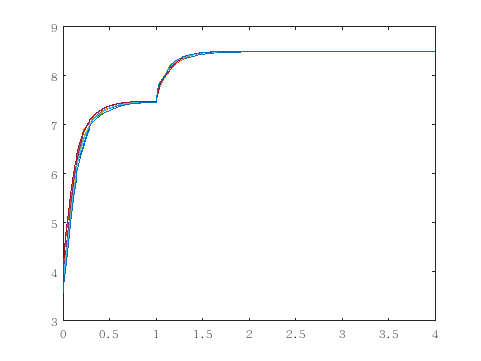


figure;
plot(tt,wrpm_431);
hold on;
plot(tt,wrpm_430);
plot(tt,wrpm_429);
plot(tt,wrpm_428);
plot(tt,wrpm_427);
plot(tt,wrpm_426);
plot(tt,wrpm_015);
plot(tt,wrpm_013);

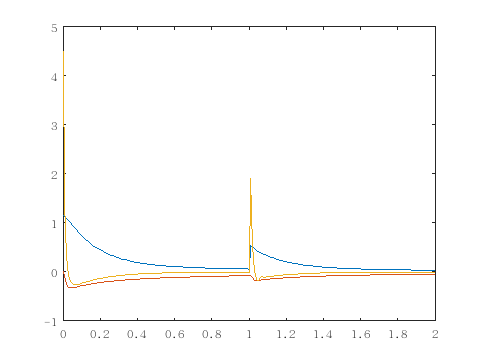


figure;
plot(t,pid_p_out);
hold on;
plot(t,pid_i_out);
plot(t,pid_d_out);

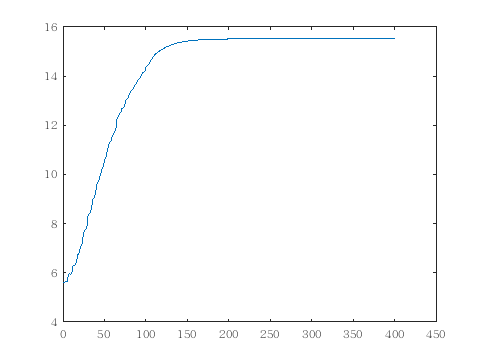

wrpm = [3.500000, 3.516834, 3.533043, 3.531626, 3.530084, 3.602102, 3.705942, 3.731232, 3.719952, 3.721078, 3.798627, 3.910339, 3.945565, 3.940504, 3.955447, 4.039815, 4.157001, 4.205570, 4.211692, 4.285659, 4.413176, 4.479406, 4.494470, 4.584198, 4.743166, 4.835597, 4.863492, 4.904633, 5.015467, 5.160609, 5.238945, 5.267562, 5.306310, 5.400116, 5.532990, 5.615272, 5.647057, 5.688037, 5.782674, 5.916922, 6.002228, 6.036277, 6.078795, 6.159135, 6.266439, 6.335931, 6.365077, 6.400210, 6.476476, 6.604269, 6.692113, 6.730544, 6.775576, 6.870972, 7.002511, 7.055645, 7.079634, 7.107154, 7.164375, 7.244025, 7.297468, 7.336974, 7.383465, 7.478737, 7.611027, 7.700462, 7.742614, 7.789570, 7.833879, 7.886614, 7.922490, 7.939657, 7.958578, 7.996559, 8.073674, 8.127592, 8.153713, 8.182250, 8.239106, 8.311789, 8.347779, 8.365396, 8.384499, 8.422319, 8.474538, 8.510556, 8.528343, 8.547503, 8.585239, 8.637299, 8.673332, 8.691263, 8.710467, 8.748118, 8.800024, 8.836065, 8.854119, 8.873357, 8.910924, 8.962685, 8.998726, 9.016889, 9.050601, 9.101482, 9.138618, 9.159699, 9.180350, 9.214236, 9.257444, 9.293549, 9.309609, 9.320569, 9.335332, 9.353121, 9.370042, 9.385027, 9.397638, 9.410745, 9.424855, 9.438277, 9.451044, 9.463189, 9.474741, 9.485729, 9.496181, 9.506124, 9.515582, 9.524578, 9.533135, 9.541275, 9.549018, 9.556383, 9.563389, 9.570053, 9.576392, 9.582422, 9.588158, 9.593614, 9.598804, 9.603740, 9.608436, 9.612903, 9.617151, 9.621193, 9.625037, 9.628694, 9.632173, 9.635481, 9.638629, 9.641623, 9.644470, 9.647180, 9.649756, 9.652207, 9.654538, 9.656756, 9.658866, 9.660872, 9.662782, 9.664597, 9.666325, 9.667967, 9.669530, 9.671017, 9.672430, 9.673775, 9.675055, 9.676271, 9.677429, 9.678531, 9.679578, 9.680574, 9.681521, 9.682424, 9.683281, 9.684096, 9.684873, 9.685611, 9.686313, 9.686980, 9.687615, 9.688220, 9.688795, 9.689342, 9.689861, 9.690356, 9.690826, 9.691275, 9.691700, 9.692105, 9.692491, 9.692857, 9.693206, 9.693537, 9.693852, 9.694153, 9.694438, 9.694710, 9.694967, 9.695213, 9.695447, 9.695669, 9.695881, 9.696082, 9.696273, 9.696455, 9.696628, 9.696793, 9.696949, 9.697099, 9.697240, 9.697374, 9.697503, 9.697625, 9.697741, 9.697851, 9.697956, 9.698056, 9.698151, 9.698241, 9.698327, 9.698409, 9.698487, 9.698561, 9.698631, 9.698698, 9.698762, 9.698822, 9.698880, 9.698935, 9.698987, 9.699037, 9.699083, 9.699128, 9.699171, 9.699211, 9.699250, 9.699286, 9.699322, 9.699355, 9.699387, 9.699416, 9.699445, 9.699472, 9.699498, 9.699523, 9.699547, 9.699569, 9.699590, 9.699610, 9.699629, 9.699647, 9.699665, 9.699681, 9.699697, 9.699712, 9.699726, 9.699739, 9.699752, 9.699764, 9.699776, 9.699787, 9.699798, 9.699808, 9.699818, 9.699826, 9.699835, 9.699843, 9.699851, 9.699859, 9.699865, 9.699872, 9.699879, 9.699884, 9.699890, 9.699896, 9.699902, 9.699906, 9.699911, 9.699915, 9.699920, 9.699924, 9.699927, 9.699931, 9.699935, 9.699938, 9.699942, 9.699944, 9.699947, 9.699949, 9.699952, 9.699955, 9.699957, 9.699959, 9.699962, 9.699964, 9.699965, 9.699967, 9.699969, 9.699970, 9.699972, 9.699974, 9.699975, 9.699976, 9.699978, 9.699979, 9.699980, 9.699982, 9.699983, 9.699984, 9.699985, 9.699986, 9.699986, 9.699987, 9.699987, 9.699988, 9.699989, 9.699989, 9.699990, 9.699991, 9.699991, 9.699992, 9.699993, 9.699993, 9.699994, 9.699994, 9.699995, 9.699995, 9.699995, 9.699996, 9.699996, 9.699996, 9.699997, 9.699997, 9.699997, 9.699998, 9.699998, 9.699998, 9.699998, 9.699999, 9.699999, 9.699999, 9.699999, 9.699999, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000, 9.700000];
throttle_out = [0.000000, 5.698671, 8.091511, 6.994079, 4.516356, 10.986465, 58.655422, 47.034649, 45.018303, 41.913731, 64.030258, 71.360710, 63.364807, 66.507637, 67.333008, 77.346245, 114.685226, 101.536171, 101.591324, 153.936371, 153.937500, 145.064209, 142.429489, 165.294434, 172.181763, 166.111206, 192.769897, 187.817825, 213.468109, 237.907806, 218.204819, 244.258652, 238.957306, 248.037628, 260.939056, 267.622467, 266.572449, 271.380249, 320.469330, 317.328522, 311.899261, 326.365295, 325.678864, 329.971832, 351.488892, 336.453491, 339.354187, 351.564301, 394.802917, 401.827057, 387.999634, 410.029602, 403.008636, 417.095825, 429.140076, 424.486786, 436.989166, 447.312744, 482.735809, 479.754700, 462.747192, 474.253204, 478.218475, 506.299988, 523.199646, 507.938904, 516.392883, 539.293579, 550.962524, 568.980835, 556.960449, 566.554688, 570.196533, 587.659058, 594.547852, 590.711060, 606.538330, 606.358459, 642.149170, 652.638672, 641.442261, 641.986816, 657.403687, 674.847046, 679.234924, 674.853699, 690.590576, 689.385376, 699.473816, 705.004700, 716.010986, 717.879150, 718.019165, 734.620728, 759.092285, 746.255310, 757.161865, 759.195801, 780.818481, 801.991577, 788.612122, 797.919678, 837.725891, 836.107117, 832.360840, 844.822266, 851.132080, 870.252319, 873.574097, 876.733704, 893.500488, 887.055054, 894.253052, 903.956238, 910.349487, 921.749878, 930.831299, 944.267883, 950.608398, 954.149902, 958.081909, 959.588684, 962.387756, 963.318604, 973.517456, 980.307434, 985.602600, 987.257080, 991.167969, 992.842346, 995.229004, 996.270752, 996.383606, 997.519287, 997.722900, 998.418213, 998.619873, 998.738647, 999.118713, 999.429382, 999.526367, 999.680847, 999.728088, 999.739868, 999.772644, 999.781860, 999.837708, 999.857056, 999.868225, 999.902588, 999.922180, 999.939575, 999.959473, 999.972717, 999.976807, 999.982727, 999.989014, 999.992920, 999.993835, 999.994507, 999.995483, 999.996887, 999.997314, 999.998169, 999.998901, 999.999390, 999.999573, 999.999512, 999.999695, 999.999756, 999.999756, 999.999695, 999.999756, 999.999756, 999.999756, 999.999756, 999.999756, 999.999634, 999.999634, 999.999756, 999.999878, 999.999939, 1000.000000, 1000.000000, 1000.000000, 1000.000061, 1000.000122, 1000.000000, 1000.000000, 1000.000061, 1000.000061, 1000.000122, 1000.000061, 1000.000000, 1000.000000, 1000.000000, 1000.000000, 1000.000000, 1000.000000, 999.999878, 999.999878, 999.999878, 999.999878, 999.999878, 999.999878, 999.999817, 999.999878, 999.999817, 999.999817, 999.999878, 1000.000000, 1000.000000, 1000.000000, 1000.000122, 1000.000122, 1000.000122, 1000.000122, 1000.000122, 1000.000061, 1000.000000, 1000.000000, 999.999939, 1000.000000, 1000.000000, 1000.000000, 999.999939, 999.999878, 1000.000000, 1000.000000, 1000.000061, 1000.000000, 1000.000000, 1000.000000, 1000.000000, 999.999878, 999.999878, 999.999939, 1000.000000, 1000.000000, 1000.000061, 1000.000183, 1000.000183, 1000.000183, 1000.000244, 1000.000122, 1000.000061, 1000.000122, 1000.000061, 1000.000122, 1000.000183, 1000.000244, 1000.000183, 1000.000122, 1000.000122, 1000.000061, 1000.000061, 1000.000061, 1000.000122, 1000.000122, 1000.000061, 1000.000000, 1000.000000, 999.999878, 999.999878, 999.999878, 999.999817, 999.999878, 999.999878, 999.999878, 999.999939, 1000.000000, 999.999939, 999.999939, 999.999878, 999.999878, 999.999878, 1000.000000, 1000.000000, 999.999878, 999.999817, 999.999878, 999.999878, 999.999878, 1000.000000, 1000.000061, 1000.000000, 999.999939, 999.999939, 1000.000061, 1000.000061, 1000.000122, 1000.000122, 1000.000122, 1000.000122, 1000.000183, 1000.000122, 1000.000122, 1000.000183, 1000.000122, 1000.000122, 1000.000122, 1000.000183, 1000.000183, 1000.000000, 1000.000000, 1000.000122, 1000.000061, 1000.000122, 1000.000122, 1000.000061, 1000.000061, 1000.000000, 1000.000000, 999.999878, 1000.000000, 999.999939, 999.999878, 999.999878, 999.999939, 1000.000000, 1000.000061, 1000.000000, 1000.000000, 999.999939, 1000.000000, 1000.000061, 1000.000122, 1000.000122, 1000.000122, 1000.000061, 999.999939, 999.999939, 999.999878, 999.999878, 999.999878, 999.999878, 999.999878, 999.999939, 1000.000000, 1000.000061, 999.999939, 1000.000061, 1000.000061, 1000.000061, 1000.000122, 1000.000122, 1000.000122, 1000.000122, 1000.000183, 1000.000122, 1000.000183, 1000.000061, 1000.000122, 1000.000122, 1000.000122, 1000.000122, 1000.000061, 1000.000183, 1000.000244, 1000.000122, 1000.000000, 1000.000061, 1000.000061, 1000.000122, 1000.000122, 1000.000061, 1000.000061, 1000.000122, 1000.000000, 1000.000000, 1000.000061, 1000.000122, 1000.000061, 1000.000000, 1000.000000, 1000.000000, 999.999939, 999.999878, 999.999878, 1000.000000, 1000.000000, 1000.000000, 1000.000061, 1000.000000, 1000.000000, 999.999817, 999.999878, 999.999878, 999.999878, 999.999817, 1000.000000, 1000.000000, 1000.000061, 1000.000061, 1000.000000, 1000.000000, 1000.000061, 1000.000183, 1000.000122, 1000.000122, 1000.000061];
thrust = [10.330591, 10.314671, 10.301670, 10.328104, 10.295246, 10.335596, 10.323835, 10.328852, 10.340513, 10.322931, 10.312941, 10.336954, 10.311842, 10.315336, 10.295048, 10.322752, 10.304754, 10.323282, 10.331289, 10.308126, 10.316263, 10.343464, 10.302210, 10.331955, 10.303431, 10.294687, 10.328897, 10.329477, 10.317301, 10.320265, 10.318089, 10.319647, 10.307566, 10.290335, 10.323385, 10.293043, 10.332930, 10.309992, 10.305414, 10.321287, 10.301498, 10.316986, 10.313761, 10.305979, 10.319641, 10.320591, 10.323872, 10.307993, 10.326117, 10.298483, 10.321970, 10.302795, 10.320038, 10.310688, 10.318439, 10.326477, 10.315079, 10.308430, 10.327372, 10.331150, 10.302439, 10.304550, 10.326963, 10.301849, 10.308569, 10.327871, 10.327353, 10.305204, 10.311636, 10.301849, 10.323578, 10.325521, 10.289658, 10.296133, 10.335007, 10.313679, 10.301056, 10.327890, 10.343225, 10.331720, 10.345371, 10.299213, 10.303558, 10.322676, 10.335463, 10.302189, 10.295502, 10.307047, 10.315744, 10.313055, 10.290195, 10.335455, 10.338318, 10.301620, 10.327225, 10.278126, 10.341650, 10.354406, 10.293081, 10.319532, 10.321211, 10.308851, 10.302753, 10.319052, 10.303564, 10.322611, 10.310215, 10.306976, 10.309895, 10.306387, 10.288263, 10.310337, 10.310049, 10.327778, 10.325697, 10.321772, 10.306273, 10.304193, 10.326542, 10.272642, 10.325602, 10.308699, 10.318958, 10.315313, 10.323736, 10.313726, 10.309977, 10.311743, 10.321135, 10.320026, 10.322447, 10.313639, 10.304327, 10.311771, 10.318491, 10.318945, 10.330683, 10.325819, 10.290272, 10.296091, 10.317881, 10.309210, 10.297812, 10.302612, 10.327768, 10.313272, 10.340269, 10.298670, 10.311270, 10.322361, 10.304794, 10.303181, 10.320219, 10.295904, 10.300928, 10.332371, 10.317244, 10.309927, 10.307398, 10.325293, 10.321671, 10.316666, 10.307501, 10.315516, 10.306349, 10.305185, 10.336103, 10.288929, 10.327341, 10.324610, 10.315521, 10.320774, 10.325760, 10.295561, 10.318872, 10.308722, 10.289785, 10.306452, 10.320084, 10.320755, 10.306669, 10.314829, 10.317122, 10.299189, 10.292532, 10.320225, 10.315231, 10.317869, 10.328754, 10.315180, 10.305471, 10.313599, 10.312571, 10.282581, 10.340179, 10.296600, 10.314817, 10.309376, 10.321095, 10.308531, 10.326094, 10.289753, 10.307682, 10.300909, 10.307636, 10.329716, 10.317991, 10.313995, 10.306517, 10.324051, 10.293812, 10.345371, 10.318521, 10.299162, 10.306376, 10.293058, 10.318277, 10.278143, 10.312933, 10.286228, 10.292440, 10.307373, 10.287598, 10.325293, 10.325108, 10.301319, 10.310734, 10.299463, 10.293736, 10.323078, 10.317301, 10.327265, 10.288223, 10.315079, 10.310453, 10.311411, 10.288391, 10.323893, 10.311066, 10.287476, 10.304480, 10.312346, 10.313614, 10.316614, 10.319752, 10.331867, 10.317429, 10.300566, 10.306284, 10.305759, 10.305838, 10.293274, 10.319624, 10.322773, 10.307489, 10.301575, 10.314356, 10.322815, 10.293486, 10.314011, 10.306009, 10.358030, 10.303711, 10.337788, 10.317518, 10.304434, 10.303669, 10.296354, 10.319181, 10.318619, 10.293234, 10.321234, 10.323538, 10.282368, 10.292383, 10.310324, 10.336796, 10.322809, 10.303455, 10.291916, 10.295654, 10.328104, 10.309851, 10.343443, 10.918802, 12.532452, 14.956747, 16.213924, 18.972626, 21.018879, 22.671358, 24.570528, 25.373829, 26.545530, 26.473722, 27.303778, 28.738352, 30.515520, 31.506401, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 32.295506, 31.417526, 31.365599, 31.299068, 31.261765, 31.246449, 31.227787, 31.144724, 31.107410, 30.356356, 29.504255, 28.197758, 28.152418, 28.080448, 27.287443, 26.552191, 26.520445, 25.702662, 25.038147, 24.203905, 24.181824, 23.133606, 22.162077, 20.572157, 20.568953, 20.291996, 19.206470, 18.533335, 17.296860, 17.216862, 17.064444, 16.931046, 16.958866, 16.914110, 16.887321, 16.820280, 16.789518, 16.799543, 16.670982, 16.683937, 18.232162, 19.639311, 20.522079, 21.358244, 22.882559, 23.715195, 23.799519, 24.784901, 25.363842, 25.383816, 26.060287, 26.761463, 27.379280, 27.386972, 28.570076, 29.556108, 30.542780, 31.859114, 32.992935, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 31.548992, 29.660742, 27.852169, 27.254477, 26.039421, 25.130312, 24.193542, 22.794077, 21.182558, 19.657740, 17.896357, 16.031105, 14.859674, 13.939286, 12.160930, 11.098478, 9.538515, 8.375175, 7.081463, 7.097404, 6.513315, 6.511221, 6.518109, 6.516338, 6.510228, 6.507201, 6.508426, 6.511644, 6.512248, 6.518984, 6.513285, 6.509557, 6.504375, 6.508042, 6.511315, 6.509275, 6.509746, 6.670659, 7.516703, 8.192463, 9.938009, 10.704397, 11.378675, 12.930207, 13.958360, 15.046679, 15.513317, 16.213924, 18.020823, 18.010122, 19.603176, 20.894871, 20.789919, 22.118084, 23.852638, 24.305374, 25.007236, 25.845634, 26.487165, 27.132069, 27.141640, 27.998289, 29.080521, 29.100071, 29.954121, 30.738337, 31.633461, 32.580669, 32.569645, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 33.000000, 31.311573, 31.238518, 30.294914, 29.014587, 27.611410, 27.518848, 27.363987, 26.243330, 25.717768, 25.716867, 25.636988, 25.554689, 25.545732, 25.523203, 25.508356, 25.475588, 25.407106, 23.209290, 23.173765, 20.407047, 18.552057, 17.071190, 15.045528, 12.833034, 10.877134, 9.071856, 7.020436, 6.515355, 6.518004, 6.516673, 6.519197, 6.514588, 6.507403, 6.510540, 6.518521, 6.510560, 6.510221, 6.510407, 6.516806, 6.518389, 6.515547, 6.519578, 6.508327, 6.512464, 6.510783, 6.509304, 6.512251, 6.512354, 6.507158, 6.513939, 6.510008, 6.511064, 6.512238, 6.516983, 6.522047, 6.517212, 6.520216, 6.513154, 6.516417, 6.512435, 6.512803, 6.516954, 6.518785, 6.521492, 6.512960, 6.517189, 6.512028, 6.522646, 6.511539, 6.511185, 6.511639, 6.512118, 6.516183, 6.517996, 6.512154, 6.514184, 6.515547, 6.515827, 6.512275, 6.517545, 6.512966, 6.523003, 6.513730, 6.514724, 6.510119, 6.517664, 6.511962, 6.508386, 6.516355, 6.516641, 6.509909, 6.505413, 6.520247, 6.513218, 6.511436, 6.515770, 6.508765, 6.507865, 6.518345, 6.523189, 6.517408, 6.514351, 6.511327, 6.521349, 6.513242, 6.510022, 6.514693, 6.511199, 6.511946, 6.512610, 6.513470, 6.511999, 6.519341, 6.518481, 6.513144, 6.513955, 6.513498, 6.512295, 6.514256, 6.514746, 6.507605, 6.516561, 6.514378, 6.519843, 6.509254, 6.511131, 6.519941, 6.516342, 6.511184, 6.513321, 6.509098, 6.513095, 10.314209, 10.309671, 10.298420, 10.322464, 10.296629, 10.316038, 10.345051, 10.303335, 10.302368, 10.315430, 10.319975, 10.321589, 10.339231, 10.328262, 10.277140, 10.339155, 10.330912, 10.307737, 10.299925, 10.321369, 10.315720, 10.319296, 10.316807, 10.305536, 10.300123, 10.329580, 10.323660, 10.330082, 10.311003, 10.322412, 10.316351, 10.304626, 10.306599, 10.304066, 10.324102, 10.296431, 10.314322, 10.311468, 10.311026, 10.313196, 10.325876, 10.325468, 10.320621, 10.335922, 10.315680, 10.306868, 10.307072, 10.314035, 10.312109, 10.332788, 10.302042, 10.324268, 10.330408, 10.323380, 10.317062, 10.304159, 10.309427, 10.293888, 10.324553, 10.330235, 10.325260, 10.315784, 10.333204, 10.301224, 10.315668, 10.339905, 10.290405, 10.306900, 10.330509, 10.313568, 10.323744, 10.278004, 10.313429, 10.315052, 10.291992, 10.317902, 10.319611, 10.302958, 10.331226, 10.324686, 10.291136, 10.325714, 10.322477, 10.305723, 10.305851, 10.325317, 10.325428, 10.310484, 10.307158, 10.337164, 10.320581, 10.311148, 10.339701, 10.294592, 10.301645, 10.338150, 10.336069, 10.300817, 10.313211, 10.343967, 10.331121, 10.313375, 10.314198, 10.319874, 10.309332, 10.292755, 10.317890, 10.312397, 10.311579];

plot(wrpm*1.6);

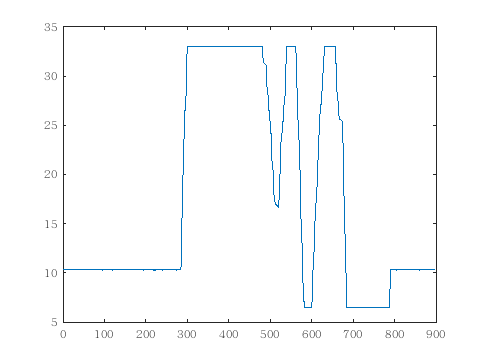

figure;
plot(thrust);

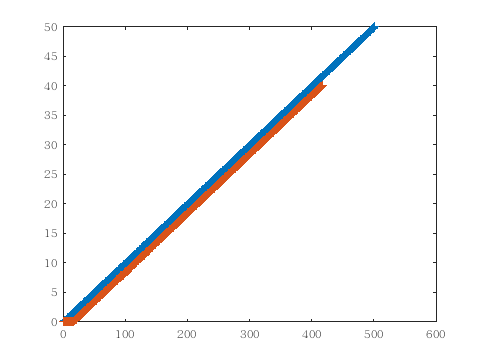

val = 0:0.1:50;
% val_delay = [0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.100000, 0.200000, 0.300000, 0.400000, 0.500000, 0.600000, 0.700000, 0.800000, 0.900000, 1.000000, 1.100000, 1.200000, 1.300000, 1.400000, 1.500000, 1.600000, 1.700000, 1.800000, 1.900000, 2.000000, 2.100000, 2.200000, 2.300000, 2.400000, 2.500000, 2.600000, 2.700000, 2.799999, 2.899999, 2.999999, 3.099999, 3.199999, 3.299999, 3.399999, 3.499999, 3.599999, 3.699999, 3.799999, 3.899998, 3.999998, 4.099998, 4.199998, 4.299998, 4.399998, 4.499998, 4.599998, 4.699998, 4.799998, 4.899998, 4.999998, 5.099998, 5.199997, 5.299997, 5.399997, 5.499997, 5.599997, 5.699997, 5.799997, 5.899997, 5.999997, 6.099997, 6.199996, 6.299996, 6.399996, 6.499996, 6.599996, 6.699996, 6.799996, 6.899996, 6.999996, 7.099996, 7.199996, 7.299995, 7.399995, 7.499995, 7.599995, 7.699995, 7.799995, 7.899995, 7.999995, 8.099995, 8.199995, 8.299995, 8.399996, 8.499996, 8.599997, 8.699997, 8.799997, 8.899998, 8.999998, 9.099998, 9.199999, 9.299999, 9.400000, 9.500000, 9.600000, 9.700001, 9.800001, 9.900002, 10.000002, 10.100002, 10.200003, 10.300003, 10.400003, 10.500004, 10.600004, 10.700005, 10.800005, 10.900005, 11.000006, 11.100006, 11.200006, 11.300007, 11.400007, 11.500008, 11.600008, 11.700008, 11.800009, 11.900009, 12.000010, 12.100010, 12.200010, 12.300011, 12.400011, 12.500011, 12.600012, 12.700012, 12.800013, 12.900013, 13.000013, 13.100014, 13.200014, 13.300014, 13.400015, 13.500015, 13.600016, 13.700016, 13.800016, 13.900017, 14.000017, 14.100018, 14.200018, 14.300018, 14.400019, 14.500019, 14.600019, 14.700020, 14.800020, 14.900021, 15.000021, 15.100021, 15.200022, 15.300022, 15.400023, 15.500023, 15.600023, 15.700024, 15.800024, 15.900024, 16.000025, 16.100025, 16.200026, 16.300026, 16.400026, 16.500027, 16.600027, 16.700027, 16.800028, 16.900028, 17.000029, 17.100029, 17.200029, 17.300030, 17.400030, 17.500031, 17.600031, 17.700031, 17.800032, 17.900032, 18.000032, 18.100033, 18.200033, 18.300034, 18.400034, 18.500034, 18.600035, 18.700035, 18.800035, 18.900036, 19.000036, 19.100037, 19.200037, 19.300037, 19.400038, 19.500038, 19.600039, 19.700039, 19.800039, 19.900040, 20.000040, 20.100040, 20.200041, 20.300041, 20.400042, 20.500042, 20.600042, 20.700043, 20.800043, 20.900043, 21.000044, 21.100044, 21.200045, 21.300045, 21.400045, 21.500046, 21.600046, 21.700047, 21.800047, 21.900047, 22.000048, 22.100048, 22.200048, 22.300049, 22.400049, 22.500050, 22.600050, 22.700050, 22.800051, 22.900051, 23.000051, 23.100052, 23.200052, 23.300053, 23.400053, 23.500053, 23.600054, 23.700054, 23.800055, 23.900055, 24.000055, 24.100056, 24.200056, 24.300056, 24.400057, 24.500057, 24.600058, 24.700058, 24.800058, 24.900059, 25.000059, 25.100060, 25.200060, 25.300060, 25.400061, 25.500061, 25.600061, 25.700062, 25.800062, 25.900063, 26.000063, 26.100063, 26.200064, 26.300064, 26.400064, 26.500065, 26.600065, 26.700066, 26.800066, 26.900066, 27.000067, 27.100067, 27.200068, 27.300068, 27.400068, 27.500069, 27.600069, 27.700069, 27.800070, 27.900070, 28.000071, 28.100071, 28.200071, 28.300072, 28.400072, 28.500072, 28.600073, 28.700073, 28.800074, 28.900074, 29.000074, 29.100075, 29.200075, 29.300076, 29.400076, 29.500076, 29.600077, 29.700077, 29.800077, 29.900078, 30.000078, 30.100079, 30.200079, 30.300079, 30.400080, 30.500080, 30.600080, 30.700081, 30.800081, 30.900082, 31.000082, 31.100082, 31.200083, 31.300083, 31.400084, 31.500084, 31.600084, 31.700085, 31.800085, 31.900085, 32.000084, 32.100082, 32.200081, 32.300079, 32.400078, 32.500076, 32.600075, 32.700073, 32.800072, 32.900070, 33.000069, 33.100067, 33.200066, 33.300064, 33.400063, 33.500061, 33.600060, 33.700058, 33.800056, 33.900055, 34.000053, 34.100052, 34.200050, 34.300049, 34.400047, 34.500046, 34.600044, 34.700043, 34.800041, 34.900040, 35.000038, 35.100037, 35.200035, 35.300034, 35.400032, 35.500031, 35.600029, 35.700027, 35.800026, 35.900024, 36.000023, 36.100021, 36.200020, 36.300018, 36.400017, 36.500015, 36.600014, 36.700012, 36.800011, 36.900009, 37.000008, 37.100006, 37.200005, 37.300003, 37.400002, 37.500000, 37.599998, 37.699997, 37.799995, 37.899994, 37.999992, 38.099991, 38.199989, 38.299988, 38.399986, 38.499985, 38.599983, 38.699982, 38.799980, 38.899979, 38.999977, 39.099976, 39.199974, 39.299973, 39.399971, 39.499969, 39.599968, 39.699966, 39.799965, 39.899963, 39.999962, 40.099960, 40.199959, 40.299957, 40.399956, 40.499954, 40.599953, 40.699951, 40.799950, 40.899948, 40.999947, 41.099945, 41.199944, 41.299942, 41.399940, 41.499939, 41.599937, 41.699936, 41.799934, 41.899933, 41.999931, 42.099930, 42.199928, 42.299927, 42.399925, 42.499924, 42.599922, 42.699921, 42.799919, 42.899918, 42.999916, 43.099915, 43.199913, 43.299911, 43.399910, 43.499908, 43.599907, 43.699905, 43.799904, 43.899902, 43.999901, 44.099899, 44.199898, 44.299896, 44.399895, 44.499893, 44.599892, 44.699890, 44.799889, 44.899887, 44.999886, 45.099884, 45.199883, 45.299881, 45.399879, 45.499878, 45.599876, 45.699875, 45.799873, 45.899872, 45.999870, 46.099869, 46.199867, 46.299866, 46.399864, 46.499863, 46.599861, 46.699860, 46.799858, 46.899857, 46.999855, 47.099854, 47.199852, 47.299850, 47.399849, 47.499847, 47.599846, 47.699844, 47.799843, 47.899841, 47.999840, 48.099838, 48.199837, 48.299835, 48.399834];
val_delay = [0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.100000, 0.200000, 0.300000, 0.400000, 0.500000, 0.600000, 0.700000, 0.800000, 0.900000, 1.000000, 1.100000, 1.200000, 1.300000, 1.400000, 1.500000, 1.600000, 1.700000, 1.800000, 1.900000, 2.000000, 2.100000, 2.200000, 2.300000, 2.400000, 2.500000, 2.600000, 2.700000, 2.799999, 2.899999, 2.999999, 3.099999, 3.199999, 3.299999, 3.399999, 3.499999, 3.599999, 3.699999, 3.799999, 3.899998, 3.999998, 4.099998, 4.199998, 4.299998, 4.399998, 4.499998, 4.599998, 4.699998, 4.799998, 4.899998, 4.999998, 5.099998, 5.199997, 5.299997, 5.399997, 5.499997, 5.599997, 5.699997, 5.799997, 5.899997, 5.999997, 6.099997, 6.199996, 6.299996, 6.399996, 6.499996, 6.599996, 6.699996, 6.799996, 6.899996, 6.999996, 7.099996, 7.199996, 7.299995, 7.399995, 7.499995, 7.599995, 7.699995, 7.799995, 7.899995, 7.999995, 8.099995, 8.199995, 8.299995, 8.399996, 8.499996, 8.599997, 8.699997, 8.799997, 8.899998, 8.999998, 9.099998, 9.199999, 9.299999, 9.400000, 9.500000, 9.600000, 9.700001, 9.800001, 9.900002, 10.000002, 10.100002, 10.200003, 10.300003, 10.400003, 10.500004, 10.600004, 10.700005, 10.800005, 10.900005, 11.000006, 11.100006, 11.200006, 11.300007, 11.400007, 11.500008, 11.600008, 11.700008, 11.800009, 11.900009, 12.000010, 12.100010, 12.200010, 12.300011, 12.400011, 12.500011, 12.600012, 12.700012, 12.800013, 12.900013, 13.000013, 13.100014, 13.200014, 13.300014, 13.400015, 13.500015, 13.600016, 13.700016, 13.800016, 13.900017, 14.000017, 14.100018, 14.200018, 14.300018, 14.400019, 14.500019, 14.600019, 14.700020, 14.800020, 14.900021, 15.000021, 15.100021, 15.200022, 15.300022, 15.400023, 15.500023, 15.600023, 15.700024, 15.800024, 15.900024, 16.000025, 16.100025, 16.200026, 16.300026, 16.400026, 16.500027, 16.600027, 16.700027, 16.800028, 16.900028, 17.000029, 17.100029, 17.200029, 17.300030, 17.400030, 17.500031, 17.600031, 17.700031, 17.800032, 17.900032, 18.000032, 18.100033, 18.200033, 18.300034, 18.400034, 18.500034, 18.600035, 18.700035, 18.800035, 18.900036, 19.000036, 19.100037, 19.200037, 19.300037, 19.400038, 19.500038, 19.600039, 19.700039, 19.800039, 19.900040, 20.000040, 20.100040, 20.200041, 20.300041, 20.400042, 20.500042, 20.600042, 20.700043, 20.800043, 20.900043, 21.000044, 21.100044, 21.200045, 21.300045, 21.400045, 21.500046, 21.600046, 21.700047, 21.800047, 21.900047, 22.000048, 22.100048, 22.200048, 22.300049, 22.400049, 22.500050, 22.600050, 22.700050, 22.800051, 22.900051, 23.000051, 23.100052, 23.200052, 23.300053, 23.400053, 23.500053, 23.600054, 23.700054, 23.800055, 23.900055, 24.000055, 24.100056, 24.200056, 24.300056, 24.400057, 24.500057, 24.600058, 24.700058, 24.800058, 24.900059, 25.000059, 25.100060, 25.200060, 25.300060, 25.400061, 25.500061, 25.600061, 25.700062, 25.800062, 25.900063, 26.000063, 26.100063, 26.200064, 26.300064, 26.400064, 26.500065, 26.600065, 26.700066, 26.800066, 26.900066, 27.000067, 27.100067, 27.200068, 27.300068, 27.400068, 27.500069, 27.600069, 27.700069, 27.800070, 27.900070, 28.000071, 28.100071, 28.200071, 28.300072, 28.400072, 28.500072, 28.600073, 28.700073, 28.800074, 28.900074, 29.000074, 29.100075, 29.200075, 29.300076, 29.400076, 29.500076, 29.600077, 29.700077, 29.800077, 29.900078, 30.000078, 30.100079, 30.200079, 30.300079, 30.400080, 30.500080, 30.600080, 30.700081, 30.800081, 30.900082, 31.000082, 31.100082, 31.200083, 31.300083, 31.400084, 31.500084, 31.600084, 31.700085, 31.800085, 31.900085, 32.000084, 32.100082, 32.200081, 32.300079, 32.400078, 32.500076, 32.600075, 32.700073, 32.800072, 32.900070, 33.000069, 33.100067, 33.200066, 33.300064, 33.400063, 33.500061, 33.600060, 33.700058, 33.800056, 33.900055, 34.000053, 34.100052, 34.200050, 34.300049, 34.400047, 34.500046, 34.600044, 34.700043, 34.800041, 34.900040, 35.000038, 35.100037, 35.200035, 35.300034, 35.400032, 35.500031, 35.600029, 35.700027, 35.800026, 35.900024, 36.000023, 36.100021, 36.200020, 36.300018, 36.400017, 36.500015, 36.600014, 36.700012, 36.800011, 36.900009, 37.000008, 37.100006, 37.200005, 37.300003, 37.400002, 37.500000, 37.599998, 37.699997, 37.799995, 37.899994, 37.999992, 38.099991, 38.199989, 38.299988, 38.399986, 38.499985, 38.599983, 38.699982, 38.799980, 38.899979, 38.999977, 39.099976, 39.199974, 39.299973, 39.399971, 39.499969, 39.599968, 39.699966, 39.799965, 39.899963, 39.999962, 40.099960];
figure;
plot(val,'+');
hold on;
plot(val_delay,'+');

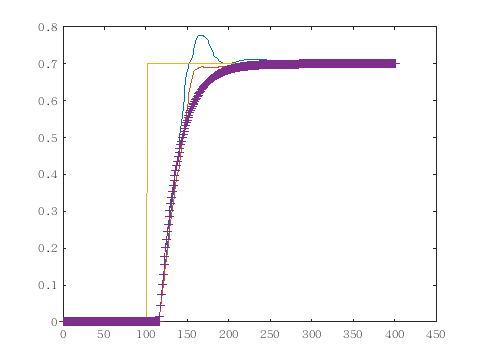

val_sp = [0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.018178, 0.039201, 0.061454, 0.083954, 0.103400, 0.120656, 0.137471, 0.152900, 0.171045, 0.191193, 0.213215, 0.235248, 0.251857, 0.270082, 0.288341, 0.308591, 0.326304, 0.342270, 0.354335, 0.371274, 0.387912, 0.402540, 0.412136, 0.422037, 0.434280, 0.446238, 0.469769, 0.492411, 0.508796, 0.522285, 0.535406, 0.548162, 0.565831, 0.583629, 0.600464, 0.615969, 0.629831, 0.642420, 0.654402, 0.666083, 0.675705, 0.679110, 0.681955, 0.684039, 0.685695, 0.687202, 0.688604, 0.689877, 0.690876, 0.691485, 0.691772, 0.691811, 0.691659, 0.691360, 0.690939, 0.690410, 0.689827, 0.689389, 0.689189, 0.689133, 0.689167, 0.689270, 0.689432, 0.689645, 0.689894, 0.690164, 0.690439, 0.690709, 0.690968, 0.691212, 0.691437, 0.691641, 0.691822, 0.691985, 0.692138, 0.692289, 0.692439, 0.692590, 0.692742, 0.692896, 0.693052, 0.693210, 0.693370, 0.693530, 0.693691, 0.693850, 0.694008, 0.694163, 0.694314, 0.694461, 0.694603, 0.694742, 0.694876, 0.695007, 0.695133, 0.695256, 0.695376, 0.695492, 0.695606, 0.695717, 0.695825, 0.695930, 0.696033, 0.696134, 0.696232, 0.696327, 0.696420, 0.696510, 0.696598, 0.696684, 0.696767, 0.696847, 0.696926, 0.697002, 0.697075, 0.697147, 0.697217, 0.697284, 0.697350, 0.697414, 0.697476, 0.697536, 0.697594, 0.697651, 0.697706, 0.697760, 0.697812, 0.697862, 0.697911, 0.697959, 0.698005, 0.698050, 0.698094, 0.698136, 0.698178, 0.698218, 0.698256, 0.698294, 0.698331, 0.698367, 0.698401, 0.698435, 0.698468, 0.698499, 0.698530, 0.698560, 0.698590, 0.698618, 0.698646, 0.698673, 0.698699, 0.698724, 0.698749, 0.698773, 0.698797, 0.698820, 0.698842, 0.698863, 0.698884, 0.698905, 0.698925, 0.698945, 0.698963, 0.698982, 0.699000, 0.699017, 0.699035, 0.699051, 0.699068, 0.699084, 0.699099, 0.699114, 0.699129, 0.699143, 0.699157, 0.699171, 0.699184, 0.699197, 0.699210, 0.699222, 0.699234, 0.699246, 0.699258, 0.699269, 0.699280, 0.699291, 0.699302, 0.699312, 0.699322, 0.699332, 0.699342, 0.699351, 0.699361, 0.699370, 0.699379, 0.699387, 0.699396, 0.699404, 0.699413, 0.699421, 0.699428, 0.699436, 0.699444, 0.699451, 0.699459, 0.699466, 0.699473, 0.699480, 0.699486, 0.699493, 0.699499, 0.699506, 0.699512, 0.699518, 0.699524, 0.699530, 0.699536, 0.699542, 0.699547, 0.699553, 0.699558, 0.699563, 0.699569, 0.699574, 0.699579, 0.699584, 0.699589, 0.699594, 0.699598, 0.699603, 0.699608, 0.699612, 0.699617, 0.699621, 0.699625, 0.699630, 0.699634, 0.699638, 0.699642, 0.699646, 0.699650, 0.699654, 0.699658, 0.699662, 0.699665, 0.699669, 0.699673, 0.699676, 0.699680, 0.699683, 0.699687, 0.699690, 0.699693, 0.699697, 0.699700, 0.699703, 0.699706, 0.699709, 0.699712, 0.699716, 0.699718, 0.699722, 0.699724, 0.699727, 0.699730, 0.699733, 0.699736, 0.699738, 0.699741, 0.699744, 0.699747, 0.699749, 0.699752, 0.699754, 0.699757, 0.699759, 0.699762, 0.699764, 0.699767, 0.699769, 0.699771, 0.699773, 0.699776, 0.699778, 0.699780];
val_wo_sp = [0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.008000, 0.018323, 0.039908, 0.063240, 0.086723, 0.107056, 0.125910, 0.143360, 0.161969, 0.182737, 0.207441, 0.232371, 0.252025, 0.272945, 0.295421, 0.317145, 0.337818, 0.351645, 0.371919, 0.391939, 0.407004, 0.418658, 0.433482, 0.448472, 0.480935, 0.505274, 0.522864, 0.540052, 0.560246, 0.584794, 0.608716, 0.632011, 0.654678, 0.675573, 0.682712, 0.689645, 0.696375, 0.702902, 0.709231, 0.715363, 0.721302, 0.729105, 0.740233, 0.750998, 0.760733, 0.768521, 0.774218, 0.776502, 0.777499, 0.777680, 0.777477, 0.777196, 0.776750, 0.776115, 0.775290, 0.773562, 0.771191, 0.768372, 0.764838, 0.760496, 0.755487, 0.749988, 0.744200, 0.738375, 0.732698, 0.727201, 0.723448, 0.720887, 0.718411, 0.716023, 0.713726, 0.711544, 0.709508, 0.707632, 0.705935, 0.704444, 0.703183, 0.702165, 0.701397, 0.700872, 0.700577, 0.700497, 0.700574, 0.700733, 0.700955, 0.701246, 0.701606, 0.702030, 0.702510, 0.703040, 0.703611, 0.704214, 0.704840, 0.705478, 0.706119, 0.706753, 0.707371, 0.707965, 0.708529, 0.709062, 0.709562, 0.710028, 0.710460, 0.710854, 0.711212, 0.711531, 0.711812, 0.712053, 0.712257, 0.712422, 0.712551, 0.712644, 0.712704, 0.712732, 0.712731, 0.712702, 0.712648, 0.712571, 0.712473, 0.712355, 0.712221, 0.712072, 0.711909, 0.711735, 0.711552, 0.711361, 0.711164, 0.710963, 0.710759, 0.710553, 0.710347, 0.710141, 0.709937, 0.709736, 0.709538, 0.709345, 0.709155, 0.708971, 0.708792, 0.708619, 0.708453, 0.708292, 0.708138, 0.707990, 0.707848, 0.707713, 0.707584, 0.707461, 0.707343, 0.707231, 0.707125, 0.707024, 0.706927, 0.706836, 0.706748, 0.706665, 0.706585, 0.706508, 0.706435, 0.706365, 0.706297, 0.706231, 0.706168, 0.706106, 0.706046, 0.705988, 0.705931, 0.705874, 0.705819, 0.705764, 0.705710, 0.705657, 0.705604, 0.705551, 0.705498, 0.705446, 0.705393, 0.705341, 0.705289, 0.705237, 0.705184, 0.705132, 0.705079, 0.705027, 0.704975, 0.704922, 0.704869, 0.704817, 0.704765, 0.704712, 0.704660, 0.704608, 0.704556, 0.704504, 0.704453, 0.704402, 0.704351, 0.704300, 0.704250, 0.704200, 0.704151, 0.704102, 0.704054, 0.704005, 0.703958, 0.703911, 0.703864, 0.703818, 0.703773, 0.703728, 0.703684, 0.703640, 0.703596, 0.703554, 0.703512, 0.703470, 0.703429, 0.703388, 0.703349, 0.703309, 0.703270, 0.703232, 0.703194, 0.703157, 0.703120, 0.703084, 0.703048, 0.703013, 0.702978, 0.702944, 0.702909, 0.702876, 0.702843, 0.702810, 0.702778, 0.702746, 0.702715, 0.702684, 0.702653, 0.702623, 0.702593, 0.702563, 0.702534, 0.702505, 0.702476, 0.702448, 0.702420, 0.702393, 0.702365, 0.702338, 0.702312, 0.702285, 0.702259, 0.702233, 0.702208, 0.702183, 0.702158, 0.702133, 0.702109, 0.702084, 0.702061, 0.702037, 0.702014, 0.701991, 0.701968, 0.701945, 0.701923, 0.701901, 0.701879, 0.701857, 0.701836, 0.701815, 0.701794, 0.701773, 0.701753, 0.701733, 0.701713, 0.701693, 0.701674, 0.701654, 0.701635, 0.701616, 0.701598, 0.701580, 0.701561, 0.701543];
val_ref = [0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000, 0.700000];

val_compare = [0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.000000, 0.015556, 0.045975, 0.075043, 0.102819, 0.129360, 0.154722, 0.178957, 0.202114, 0.224242, 0.245387, 0.265592, 0.284899, 0.303348, 0.320977, 0.337823, 0.353920, 0.369301, 0.383999, 0.398043, 0.411464, 0.424287, 0.436541, 0.448251, 0.459440, 0.470131, 0.480348, 0.490110, 0.499438, 0.508352, 0.516870, 0.525009, 0.532787, 0.540218, 0.547320, 0.554106, 0.560590, 0.566786, 0.572707, 0.578364, 0.583770, 0.588936, 0.593872, 0.598589, 0.603096, 0.607403, 0.611519, 0.615451, 0.619209, 0.622800, 0.626231, 0.629510, 0.632642, 0.635636, 0.638497, 0.641230, 0.643842, 0.646338, 0.648723, 0.651002, 0.653180, 0.655261, 0.657249, 0.659150, 0.660965, 0.662700, 0.664358, 0.665942, 0.667456, 0.668902, 0.670284, 0.671605, 0.672867, 0.674073, 0.675226, 0.676327, 0.677379, 0.678384, 0.679345, 0.680263, 0.681140, 0.681979, 0.682780, 0.683545, 0.684276, 0.684975, 0.685643, 0.686281, 0.686891, 0.687474, 0.688030, 0.688563, 0.689071, 0.689557, 0.690021, 0.690464, 0.690888, 0.691293, 0.691680, 0.692050, 0.692404, 0.692741, 0.693064, 0.693372, 0.693667, 0.693948, 0.694217, 0.694474, 0.694720, 0.694955, 0.695179, 0.695393, 0.695598, 0.695794, 0.695981, 0.696160, 0.696330, 0.696493, 0.696649, 0.696798, 0.696941, 0.697077, 0.697207, 0.697331, 0.697450, 0.697563, 0.697671, 0.697775, 0.697874, 0.697968, 0.698059, 0.698145, 0.698228, 0.698306, 0.698382, 0.698454, 0.698523, 0.698588, 0.698651, 0.698711, 0.698768, 0.698823, 0.698876, 0.698926, 0.698973, 0.699019, 0.699063, 0.699104, 0.699144, 0.699182, 0.699219, 0.699253, 0.699287, 0.699319, 0.699349, 0.699378, 0.699406, 0.699432, 0.699457, 0.699481, 0.699505, 0.699527, 0.699548, 0.699568, 0.699587, 0.699606, 0.699623, 0.699640, 0.699656, 0.699671, 0.699686, 0.699700, 0.699713, 0.699726, 0.699738, 0.699750, 0.699761, 0.699772, 0.699782, 0.699792, 0.699801, 0.699810, 0.699819, 0.699827, 0.699834, 0.699842, 0.699849, 0.699856, 0.699862, 0.699868, 0.699874, 0.699880, 0.699885, 0.699890, 0.699895, 0.699900, 0.699905, 0.699909, 0.699913, 0.699917, 0.699921, 0.699924, 0.699928, 0.699931, 0.699934, 0.699937, 0.699940, 0.699943, 0.699945, 0.699948, 0.699950, 0.699952, 0.699955, 0.699957, 0.699959, 0.699960, 0.699962, 0.699964, 0.699966, 0.699967, 0.699969, 0.699970, 0.699972, 0.699973, 0.699974, 0.699975, 0.699976, 0.699978, 0.699979, 0.699980, 0.699981, 0.699981, 0.699982, 0.699983, 0.699984, 0.699985, 0.699985, 0.699986, 0.699987, 0.699987, 0.699988, 0.699989, 0.699989, 0.699990, 0.699990, 0.699991, 0.699991, 0.699992, 0.699992, 0.699992, 0.699993, 0.699993, 0.699994, 0.699994, 0.699994, 0.699995, 0.699995, 0.699995, 0.699995, 0.699996, 0.699996, 0.699996, 0.699996, 0.699997, 0.699997, 0.699997, 0.699997, 0.699997, 0.699998, 0.699998, 0.699998, 0.699998, 0.699998, 0.699998, 0.699998, 0.699998, 0.699999, 0.699999, 0.699999, 0.699999, 0.699999, 0.699999, 0.699999, 0.699999, 0.699999, 0.699999];
figure;
plot(val_wo_sp);
hold on;
plot(val_sp);
plot(val_ref);
plot(val_compare,'+');